clc
clear all
load('liftSurfGeom.mat')
% This script is used to determine the web thickness of the wing spars

% N.B. Spars are placed at 20 % and 60 %

% Spar material: Al-7055, T76511
% E=73.5 GPa

E=7.35*10^10;
K=8.1;
% The first step is to discretise into stations:

span = 12.165; 
no_stations = 100;
spanwise_coordinates = 0:span/(no_stations-1):span;

% Now find the shear force at each location. Use function Roherz

SF_i=zeros(1,no_stations);
SF_a=zeros(1,no_stations);
for i=1:no_stations
    SF_i(i)=-1*Roherz(spanwise_coordinates(i));
    SF_a(i)=aeroShear(wing,spanwise_coordinates(i));
end

ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0



SF=(SF_i-SF_a)*3.75;

% Now find the wing torque at each location. 

ds=(12.165)/(no_stations-1);
[dist,torque,torque_ult] = RCMK_Spars(ds);

dist =          0    0.1229    0.2458    0.3686    0.4915    0.6144    0.7373    0.8602    0.9830    1.1059    1.2288    1.3517    1.4745    1.5974    1.7203    1.8432    1.9661    2.0889    2.2118    2.3347    2.4576    2.5805    2.7033    2.8262    2.9491    3.0720    3.1948    3.3177    3.4406    3.5635    3.6864    3.8092    3.9321    4.0550    4.1779    4.3008    4.4236    4.5465    4.6694    4.7923    4.9152    5.0380    5.1609    5.2838    5.4067    5.5295    5.6524    5.7753    5.8982    6.0211


torque_ult

torque_ult = 1.0e+05 *

    4.5854    4.5854    4.5854    4.5854   -1.4943   -1.4630   -1.4318   -1.4006   -1.3696   -1.3387   -1.3079   -1.2772   -1.2466    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254    1.2254   -1.4261   -1.3976   -1.3692   -1.3410   -1.3129   -1.2850   -1.2572   -1.2296   -1.2022   -1.1750   -1.1479   -1.1210   -1.0943   -1.0678   -1.0414   -1.0153   -0.9893   -0.9635   -0.9380   -0.9126   -0.8874   -0.8625   -0.8377


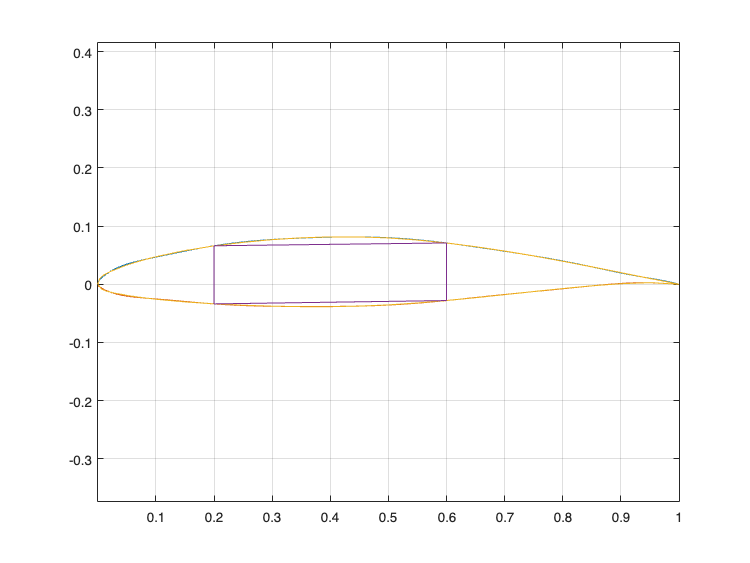

% Now, find the shear flow due to shear force: q2

syms x;
root_chord=4.073949602;
tip_chord=1.756951274;
c = ((tip_chord-root_chord)/span)*x + root_chord;

for i=1:no_stations
    c_r(i)=subs(c,x,spanwise_coordinates(i));
end

coords=wingbox(wing);

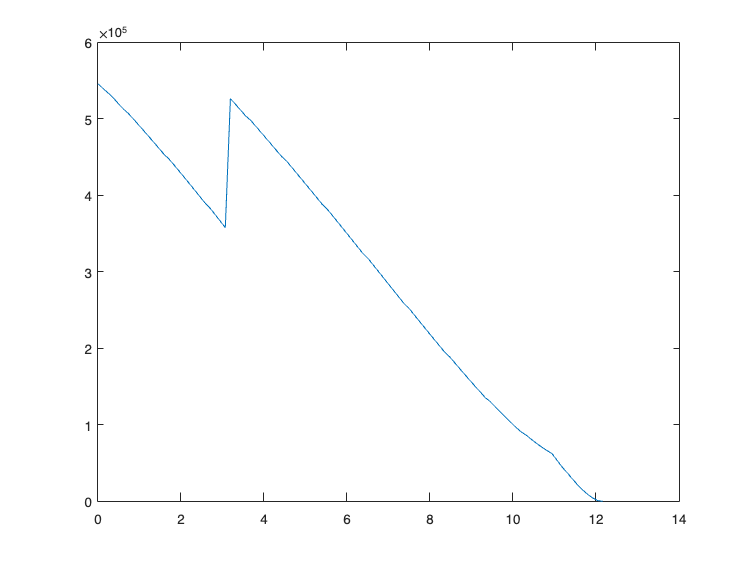

h_r =zeros(1,no_stations); % Depth of wing box along chord (m)

for j=1:no_stations
    h_r(j) = c_r(j)*((coords(1,2)-coords(2,2))+(coords(4,2)-coords(3,2)))/2;
end

q2 = -(SF./(2.*h_r));

% Now, find the shear flow due to shear force: q02

q02 = -(torque_ult./(2.*h_r.*0.4.*double(c_r)));

% Now, find t_f and t_r:

t_f = ((1/(K*E))*((q2+q02).*h_r)).^(1/3);
t_r = ((1/(K*E))*((q2-q02).*h_r)).^(1/3);

plot(spanwise_coordinates,q2)

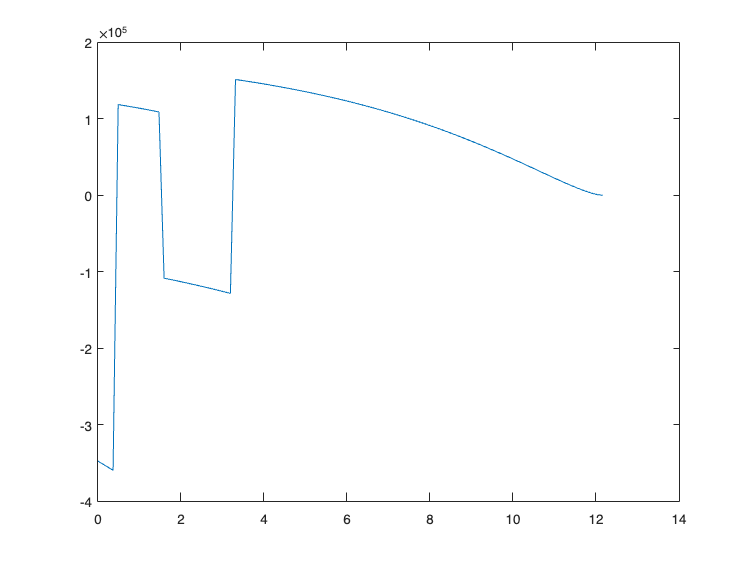


plot(spanwise_coordinates,q02)

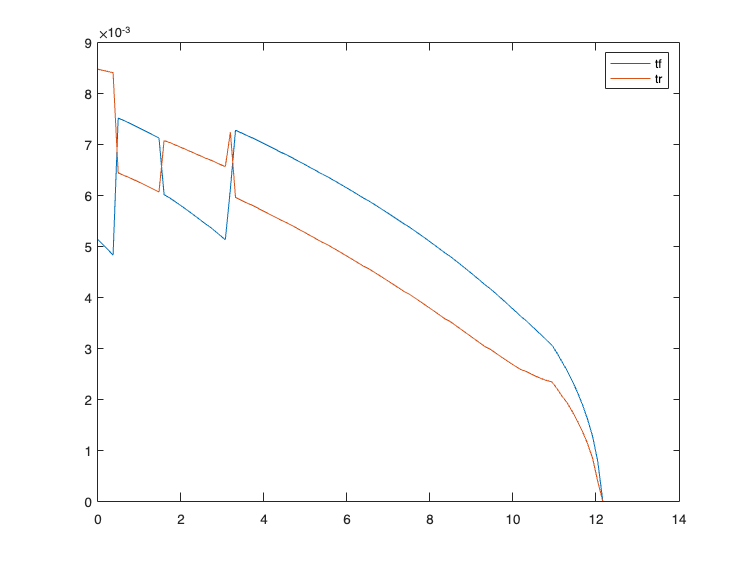


figure()
plot(spanwise_coordinates,t_f)
hold on
plot(spanwise_coordinates,t_r)

legend("tf","tr")

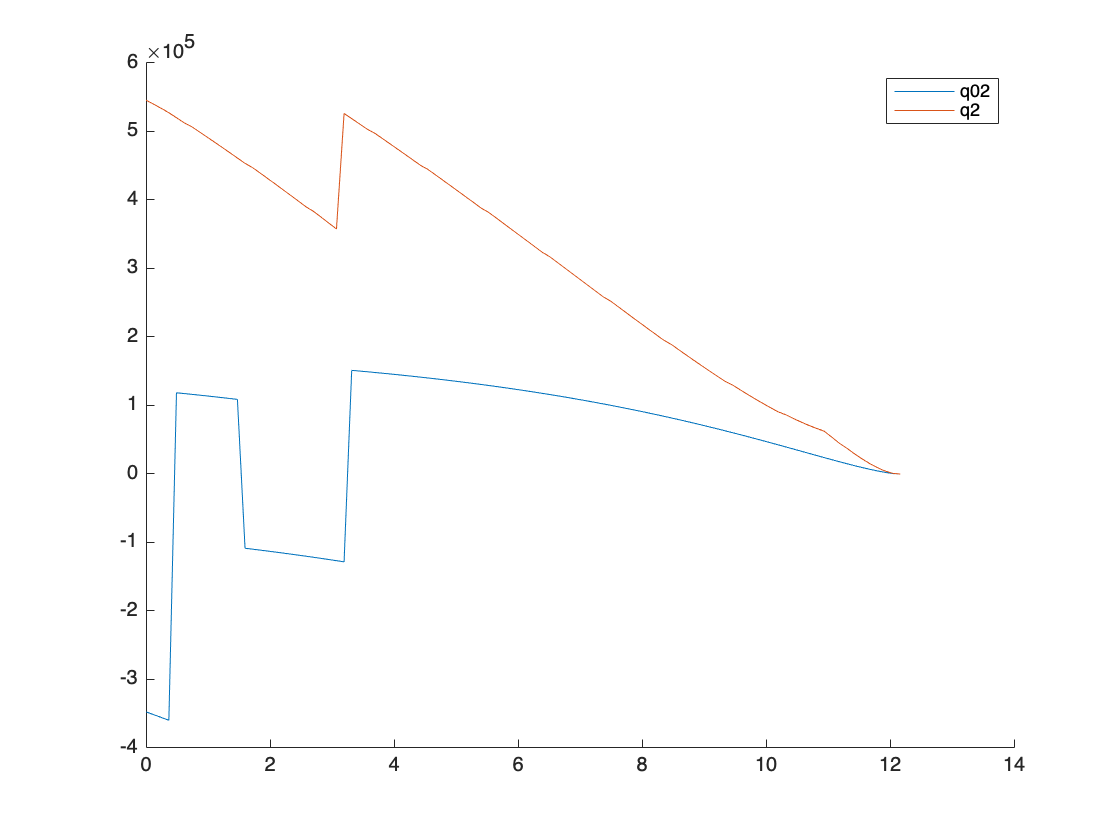


figure
hold on
plot(spanwise_coordinates,q02)
plot(spanwise_coordinates,q2)
legend('q02','q2')
hold off

% Chord dist

dist=spanwise_coordinates

dist =          0    0.1229    0.2458    0.3686    0.4915    0.6144    0.7373    0.8602    0.9830    1.1059    1.2288    1.3517    1.4745    1.5974    1.7203    1.8432    1.9661    2.0889    2.2118    2.3347    2.4576    2.5805    2.7033    2.8262    2.9491    3.0720    3.1948    3.3177    3.4406    3.5635    3.6864    3.8092    3.9321    4.0550    4.1779    4.3008    4.4236    4.5465    4.6694    4.7923    4.9152    5.0380    5.1609    5.2838    5.4067    5.5295    5.6524    5.7753    5.8982    6.0211


span = 12.165

span = 12.1650

root_chord=4.073949602;
tip_chord=1.756951274;

c = double(c_r)

c =     4.0739    4.0505    4.0271    4.0037    3.9803    3.9569    3.9335    3.9101    3.8867    3.8633    3.8399    3.8165    3.7931    3.7697    3.7463    3.7229    3.6995    3.6761    3.6527    3.6293    3.6059    3.5825    3.5591    3.5357    3.5123    3.4888    3.4654    3.4420    3.4186    3.3952    3.3718    3.3484    3.3250    3.3016    3.2782    3.2548    3.2314    3.2080    3.1846    3.1612    3.1378    3.1144    3.0910    3.0676    3.0442    3.0208    2.9974    2.9740    2.9506    2.9272



% M dist
for i=1:length(spanwise_coordinates)
    BM_i(i)=Remerz(spanwise_coordinates(i));
    BM_a(i)=aeroMom(wing,spanwise_coordinates(i));
end

BM = 3.75*(BM_a+BM_i)

BM = 1.0e+06 *

    3.7621    3.6897    3.6182    3.5476    3.4780    3.4095    3.3439    3.2774    3.2118    3.1473    3.0838    3.0213    2.9598    2.8993    2.8418    2.7833    2.7258    2.6694    2.6139    2.5594    2.5059    2.4534    2.4039    2.3534    2.3039    2.2554    2.2060    2.1444    2.0838    2.0242    1.9675    1.9098    1.8530    1.7973    1.7425    1.6886    1.6357    1.5856    1.5346    1.4846    1.4354    1.3872    1.3400    1.2936    1.2482    1.2054    1.1618    1.1191    1.0773    1.0364



% Sigma, yield
sigma = 650*10^6;

coords=wingbox(wing);

D = h_r;
t1=[]


t1 =

     []



b=[]


b =

     []



A=[]


A =

     []



                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.571141e-03    1.091e-03    1.033e-02
    1       6    5.724118e-03    1.033e-03    1.518e-03    2.801e-02
    2      10    7.466033e-03    9.800e-04    1.712e-03    1.475e-02
    3      13    9.532441e-03    8.961e-04    7.674e-03    4.691e-02
    4      16    1.089962e-02    8.134e-04    2.820e-06    1.553e-01
    5      19    3.068557e-02    2.786e-04    1.225e-04    4.091e-02
    6      22    4.056732e-02    9.814e-05    1.344e-06    1.977e-02
    7      25    4.578930e-02    2.473e-05    1.379e-05    1.069e-02
    8      28    4.771061e-02    8.357e-07    9.054e-06    3.912e-03
    9      31    4.777340e-02    6.133e-10    1.999e-06    1.201e-04
   10      34    4.777148e-02    4.857e-12    2.273e-08    1.229e-05

Local minimum found that satisfies the cons

minArea_dims =     0.0933    0.2500


A = 0.0478

t1 = 0.0933

b = 0.2500

A = 0.0478

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.525840e-03    1.064e-03    1.038e-02
    1       6    5.693643e-03    1.005e-03    1.523e-03    2.799e-02
    2      10    7.488909e-03    9.522e-04    1.719e-03    1.484e-02
    3      13    9.859366e-03    8.618e-04    7.211e-03    4.559e-02
    4      16    8.808817e-03    8.593e-04    1.632e-06    1.569e-01
    5      19    2.694195e-02    3.711e-04    1.171e-02    5.499e-02
    6      22    3.588887e-02    1.600e-04    1.388e-05    3.416e-02
    7      25    4.339288e-02    4.302e-05    2.328e-06    1.528e-02
    8      28    4.654356e-02    2.347e-06    1.179e-05    6.449e-03
    9      31    4.672580e-02    6.278e-09    1.899e-06    3.565e-04
   10      34    4.672444e-02    3.729e-12    2.203e-08    1.165e-05

Local minimum found that satisfies the cons

minArea_dims =     0.0912    0.2500


A = 0.0467

t1 =     0.0933    0.0912


b =     0.2500    0.2500


A =     0.0478    0.0467


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.479636e-03    1.037e-03    1.044e-02
    1       6    5.662944e-03    9.785e-04    1.529e-03    2.797e-02
    2       9    6.975077e-03    9.329e-04    4.333e-03    2.024e-02
    3      13    1.154761e-02    7.963e-04    1.930e-02    4.037e-02
    4      16    1.658116e-02    5.998e-04    1.057e-03    1.169e-01
    5      19    3.217881e-02    2.119e-04    1.206e-05    4.630e-02
    6      22    4.151314e-02    5.576e-05    1.275e-07    1.900e-02
    7      25    4.541396e-02    3.635e-06    1.763e-06    7.962e-03
    8      28    4.570591e-02    1.942e-08    2.000e-06    5.961e-04
    9      31    4.570550e-02    2.532e-12    2.173e-08    1.189e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims =     0.0892    0.2500


A = 0.0457

t1 =     0.0933    0.0912    0.0892


b =     0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.431278e-03    1.010e-03    1.048e-02
    1       6    5.631379e-03    9.522e-04    1.535e-03    2.796e-02
    2       9    6.971315e-03    9.063e-04    4.343e-03    2.049e-02
    3      13    1.157790e-02    7.702e-04    1.940e-02    4.098e-02
    4      16    1.683327e-02    5.698e-04    1.009e-03    1.177e-01
    5      19    3.230486e-02    1.931e-04    1.171e-05    4.467e-02
    6      22    4.156091e-02    4.172e-05    1.231e-07    1.883e-02
    7      25    4.454566e-02    2.115e-06    1.586e-06    6.090e-03
    8      28    4.471418e-02    6.540e-09    2.002e-06    3.445e-04
    9      31    4.471273e-02    4.792e-12    2.169e-08    1.353e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims =     0.0873    0.2500


A = 0.0447

t1 =     0.0933    0.0912    0.0892    0.0873


b =     0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.324297e-03    9.749e-04    1.112e-02
    1       6    6.118224e-03    9.301e-04    1.680e-02    2.927e-02
    2       9    7.107993e-03    9.007e-04    1.595e-03    9.446e-03
    3      12    7.953510e-03    8.611e-04    8.549e-03    3.336e-02
    4      16    1.511928e-02    6.463e-04    1.415e-02    6.880e-02
    5      19    2.404067e-02    3.632e-04    1.481e-05    1.097e-01
    6      22    3.763806e-02    9.428e-05    3.682e-05    2.805e-02
    7      25    4.351780e-02    8.414e-06    2.903e-07    1.202e-02
    8      28    4.416328e-02    9.879e-08    2.079e-06    1.335e-03
    9      31    4.416896e-02    4.628e-13    2.052e-08    1.477e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims =     0.0849    0.2500


A = 0.0442

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849


b =     0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.290821e-03    9.494e-04    1.119e-02
    1       6    6.091371e-03    9.050e-04    1.694e-02    2.921e-02
    2       9    7.084828e-03    8.758e-04    1.600e-03    9.642e-03
    3      12    7.888455e-03    8.373e-04    8.701e-03    3.433e-02
    4      16    1.522294e-02    6.196e-04    1.341e-02    7.117e-02
    5      19    2.465394e-02    3.306e-04    1.556e-05    1.063e-01
    6      22    3.793427e-02    7.595e-05    3.536e-05    2.739e-02
    7      25    4.280558e-02    5.697e-06    2.582e-07    9.944e-03
    8      28    4.324137e-02    4.542e-08    2.054e-06    9.025e-04
    9      31    4.324285e-02    6.746e-13    2.106e-08    1.355e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims =     0.0831    0.2500


A = 0.0432

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849    0.0831


b =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442    0.0432


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.259419e-03    9.249e-04    1.126e-02
    1       6    6.065771e-03    8.810e-04    1.708e-02    2.917e-02
    2       9    7.061922e-03    8.520e-04    1.604e-03    9.820e-03
    3      12    7.827430e-03    8.146e-04    8.826e-03    3.519e-02
    4      16    4.777148e-02    6.156e-05    2.604e-03    1.844e-01
    5      19    4.177949e-02    8.439e-06    2.874e-05    1.264e-02
    6      22    4.239363e-02    7.804e-08    9.195e-06    1.227e-03
    7      25    4.239244e-02    4.549e-11    2.017e-06    5.351e-05
    8      28    4.239045e-02    7.443e-12    2.150e-08    1.643e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims =     0.0814    0.2500


A = 0.0424

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814


b =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.226004e-03    9.004e-04    1.134e-02
    1       6    6.039127e-03    8.569e-04    1.722e-02    2.911e-02
    2       9    7.039005e-03    8.280e-04    1.609e-03    1.002e-02
    3      12    7.767214e-03    7.917e-04    8.589e-03    3.611e-02
    4      16    4.601155e-02    5.272e-05    9.390e-04    1.827e-01
    5      19    4.109593e-02    5.856e-06    2.326e-05    1.042e-02
    6      22    4.152046e-02    3.716e-08    9.596e-06    8.474e-04
    7      25    4.151570e-02    8.494e-11    2.019e-06    6.227e-05
    8      28    4.151371e-02    7.893e-12    2.145e-08    1.718e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims =     0.0796    0.2500


A = 0.0415

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796


b =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.192615e-03    8.764e-04    1.141e-02
    1       6    6.012591e-03    8.334e-04    1.737e-02    2.906e-02
    2       9    7.016229e-03    8.046e-04    1.614e-03    1.023e-02
    3      12    7.709669e-03    7.693e-04    8.287e-03    3.700e-02
    4      16    4.433096e-02    4.394e-05    1.518e-04    1.810e-01
    5      19    4.038770e-02    3.901e-06    1.903e-05    8.417e-03
    6      22    4.066117e-02    1.325e-08    1.700e-06    5.375e-04
    7      25    4.066049e-02    3.684e-12    2.097e-08    1.416e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims =     0.0779    0.2500


A = 0.0407

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779


b =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.159250e-03    8.529e-04    1.149e-02
    1       6    5.986166e-03    8.103e-04    1.752e-02    2.901e-02
    2       9    6.993597e-03    7.818e-04    1.620e-03    1.044e-02
    3      12    7.654816e-03    7.474e-04    8.004e-03    3.786e-02
    4      16    4.272936e-02    3.530e-05    1.355e-04    1.793e-01
    5      19    3.966329e-02    2.456e-06    1.604e-05    6.611e-03
    6      22    3.983134e-02    4.415e-09    1.857e-06    3.310e-04
    7      25    3.982984e-02    6.570e-12    2.118e-08    1.688e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims =     0.0763    0.2500


A = 0.0398

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763


b =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.125909e-03    8.299e-04    1.157e-02
    1       6    5.959852e-03    7.878e-04    1.768e-02    2.896e-02
    2       9    6.971116e-03    7.594e-04    1.625e-03    1.066e-02
    3      12    7.602642e-03    7.258e-04    7.740e-03    3.870e-02
    4      16    4.120532e-02    2.689e-05    1.213e-04    1.777e-01
    5      19    3.892921e-02    1.428e-06    1.381e-05    4.990e-03
    6      22    3.902273e-02    1.018e-09    1.942e-06    1.910e-04
    7      25    3.902089e-02    8.404e-12    2.128e-08    1.872e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims =     0.0747    0.2500


A = 0.0390

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747


b =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.092590e-03    8.075e-04    1.165e-02
    1       6    5.933653e-03    7.658e-04    1.784e-02    2.891e-02
    2       9    6.948790e-03    7.375e-04    1.630e-03    1.088e-02
    3      12    7.553113e-03    7.048e-04    7.493e-03    3.952e-02
    4      16    3.975658e-02    1.879e-05    1.088e-04    1.762e-01
    5      19    3.819130e-02    7.316e-07    1.220e-05    3.541e-03
    6      22    3.823480e-02    6.075e-11    1.987e-06    1.111e-04
    7      25    3.823284e-02    9.519e-12    2.133e-08    2.006e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims =     0.0731    0.2500


A = 0.0382

t1 =     0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731


b =     0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A =     0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    4.059291e-03    7.855e-04    1.173e-02
    1       6    5.907571e-03    7.442e-04    1.800e-02    2.886e-02
    2       9    6.926627e-03    7.161e-04    1.635e-03    1.110e-02
    3      12    7.506173e-03    6.841e-04    7.263e-03    4.032e-02
    4      16    3.838031e-02    1.104e-05    9.816e-05    1.747e-01
    5      19    3.745425e-02    2.980e-07    1.107e-05    2.263e-03
    6      22    3.746696e-02    1.944e-12    2.009e-06    8.587e-05
    7      25    3.746497e-02    1.027e-11    2.178e-08    2.116e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0716    0.2500


A = 0.0375

t1 = 1×13
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716


b = 1×13
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×13
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.693083e-03    7.668e-04    1.157e-02
    1       6    5.705267e-03    7.218e-04    1.505e-03    2.819e-02
    2       9    6.541575e-03    6.930e-04    5.830e-03    2.014e-02
    3      13    1.066228e-02    5.855e-04    1.561e-02    3.837e-02
    4      16    1.497927e-02    4.353e-04    1.190e-03    1.132e-01
    5      19    3.152619e-02    7.547e-05    1.551e-05    5.465e-02
    6      22    3.616651e-02    5.363e-06    3.312e-06    9.463e-03
    7      25    3.655070e-02    3.491e-08    1.947e-06    7.834e-04
    8      28    3.655132e-02    3.226e-12    2.086e-08    1.950e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0703    0.2500


A = 0.0366

t1 = 1×14
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703


b = 1×14
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×14
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.661218e-03    7.463e-04    1.165e-02
    1       6    5.681564e-03    7.019e-04    1.510e-03    2.816e-02
    2       9    6.526411e-03    6.732e-04    5.893e-03    2.028e-02
    3      13    1.071049e-02    5.658e-04    1.604e-02    3.871e-02
    4      16    1.493033e-02    4.191e-04    1.069e-03    1.145e-01
    5      19    3.153263e-02    6.449e-05    1.513e-05    5.335e-02
    6      22    3.557537e-02    4.043e-06    4.749e-06    8.243e-03
    7      25    3.586329e-02    1.893e-08    1.926e-06    5.822e-04
    8      28    3.586276e-02    6.126e-12    2.103e-08    2.075e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0689    0.2500


A = 0.0359

t1 = 1×15
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689


b = 1×15
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×15
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.626314e-03    7.258e-04    1.173e-02
    1       6    5.656445e-03    6.818e-04    1.516e-03    2.813e-02
    2       9    6.513163e-03    6.531e-04    5.953e-03    2.043e-02
    3      13    1.077422e-02    5.456e-04    1.659e-02    3.908e-02
    4      16    1.487111e-02    4.030e-04    9.444e-04    1.159e-01
    5      19    3.153888e-02    5.335e-05    1.470e-05    5.198e-02
    6      22    3.494883e-02    2.857e-06    6.076e-06    6.951e-03
    7      25    3.514994e-02    8.661e-09    1.928e-06    4.019e-04
    8      28    3.514866e-02    8.739e-12    2.115e-08    2.224e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0675    0.2500


A = 0.0351

t1 = 1×16
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675


b = 1×16
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×16
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.591284e-03    7.058e-04    1.180e-02
    1       6    5.631435e-03    6.622e-04    1.521e-03    2.810e-02
    2       9    6.500272e-03    6.335e-04    6.013e-03    2.059e-02
    3      13    1.084095e-02    5.259e-04    1.716e-02    3.946e-02
    4      16    1.481976e-02    3.871e-04    8.328e-04    1.173e-01
    5      19    3.154772e-02    4.259e-05    1.425e-05    5.062e-02
    6      22    3.432426e-02    1.880e-06    7.198e-06    5.658e-03
    7      25    3.445400e-02    3.162e-09    1.945e-06    2.566e-04
    8      28    3.445231e-02    1.074e-11    2.124e-08    2.373e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0662    0.2500


A = 0.0345

t1 = 1×17
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662


b = 1×17
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×17
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.556113e-03    6.862e-04    1.188e-02
    1       6    5.606535e-03    6.430e-04    1.527e-03    2.807e-02
    2       9    6.487763e-03    6.144e-04    6.074e-03    2.075e-02
    3      13    1.091088e-02    5.066e-04    1.776e-02    3.986e-02
    4      16    1.477598e-02    3.715e-04    7.325e-04    1.186e-01
    5      19    3.155962e-02    3.220e-05    1.378e-05    4.929e-02
    6      22    3.370160e-02    1.110e-06    8.126e-06    4.362e-03
    7      25    3.377509e-02    7.203e-10    1.969e-06    1.502e-04
    8      28    3.377319e-02    1.221e-11    2.130e-08    2.516e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0648    0.2500


A = 0.0338

t1 = 1×18
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648


b = 1×18
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×18
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.520787e-03    6.671e-04    1.195e-02
    1       6    5.581744e-03    6.244e-04    1.533e-03    2.804e-02
    2       9    6.475663e-03    5.957e-04    6.135e-03    2.092e-02
    3      13    1.098421e-02    4.878e-04    1.839e-02    4.026e-02
    4      16    1.473955e-02    3.562e-04    6.422e-04    1.200e-01
    5      19    3.157500e-02    2.219e-05    1.331e-05    4.799e-02
    6      22    3.308074e-02    5.436e-07    8.875e-06    3.064e-03
    7      25    3.311282e-02    5.200e-12    1.993e-06    9.591e-05
    8      28    3.311085e-02    1.331e-11    2.135e-08    2.655e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0635    0.2500


A = 0.0331

t1 = 1×19
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635


b = 1×19
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×19
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.485288e-03    6.484e-04    1.203e-02
    1       6    5.557063e-03    6.062e-04    1.539e-03    2.802e-02
    2       9    6.464004e-03    5.775e-04    6.197e-03    2.110e-02
    3      13    1.106117e-02    4.694e-04    1.906e-02    4.068e-02
    4      16    1.471026e-02    3.412e-04    5.607e-04    1.213e-01
    5      19    3.153761e-02    1.334e-05    1.275e-05    4.664e-02
    6      22    3.245981e-02    2.016e-07    9.423e-06    1.874e-03
    7      25    3.246684e-02    3.290e-11    2.010e-06    9.648e-05
    8      28    3.246485e-02    1.418e-11    2.138e-08    2.786e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0623    0.2500


A = 0.0325

t1 = 1×20
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623


b = 1×20
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×20
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.449596e-03    6.303e-04    1.211e-02
    1       6    5.532492e-03    5.884e-04    1.545e-03    2.799e-02
    2       9    6.452818e-03    5.598e-04    6.260e-03    2.128e-02
    3      13    1.113513e-02    4.515e-04    1.970e-02    4.111e-02
    4      16    1.470078e-02    3.261e-04    4.899e-04    1.226e-01
    5      19    3.088522e-02    1.366e-05    1.150e-05    4.447e-02
    6      22    3.182905e-02    2.134e-07    9.545e-06    1.922e-03
    7      25    3.183678e-02    3.281e-11    2.010e-06    1.023e-04
    8      28    3.183479e-02    1.483e-11    2.140e-08    2.897e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0611    0.2500


A = 0.0318

t1 = 1×21
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611


b = 1×21
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×21
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.413691e-03    6.125e-04    1.219e-02
    1       6    5.508029e-03    5.711e-04    1.551e-03    2.796e-02
    2       9    6.442143e-03    5.425e-04    6.323e-03    2.147e-02
    3      13    1.113899e-02    4.353e-04    1.970e-02    4.153e-02
    4      16    1.483229e-02    3.085e-04    4.524e-04    1.236e-01
    5      19    3.030011e-02    1.323e-05    1.045e-05    4.228e-02
    6      22    3.121547e-02    2.023e-07    9.679e-06    1.867e-03
    7      25    3.122227e-02    4.725e-11    2.011e-06    1.089e-04
    8      28    3.122028e-02    1.551e-11    2.141e-08    3.013e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0599    0.2500


A = 0.0312

t1 = 1×22
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599


b = 1×22
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×22
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.380889e-03    5.958e-04    1.227e-02
    1       6    5.485259e-03    5.548e-04    1.556e-03    2.794e-02
    2       9    6.429858e-03    5.262e-04    6.391e-03    2.165e-02
    3      13    1.114300e-02    4.201e-04    1.971e-02    4.194e-02
    4      16    1.494614e-02    2.924e-04    4.148e-04    1.245e-01
    5      19    2.976119e-02    1.291e-05    9.531e-06    4.025e-02
    6      22    3.065694e-02    1.950e-07    9.791e-06    1.830e-03
    7      25    3.066313e-02    5.959e-11    2.012e-06    1.149e-04
    8      28    3.066114e-02    1.613e-11    2.143e-08    3.122e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0588    0.2500


A = 0.0307

t1 = 1×23
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588


b = 1×23
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×23
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.344545e-03    5.789e-04    1.235e-02
    1       6    5.461022e-03    5.383e-04    1.563e-03    2.792e-02
    2       9    6.420240e-03    5.098e-04    6.455e-03    2.186e-02
    3      13    1.114927e-02    4.047e-04    1.972e-02    4.240e-02
    4      16    1.508967e-02    2.755e-04    3.767e-04    1.255e-01
    5      19    2.920290e-02    1.250e-05    8.597e-06    3.804e-02
    6      22    3.007303e-02    1.855e-07    9.904e-06    1.781e-03
    7      25    3.007843e-02    7.580e-11    2.013e-06    1.217e-04
    8      28    3.007645e-02    1.684e-11    2.145e-08    3.244e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0576    0.2500


A = 0.0301

t1 = 1×24
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576


b = 1×24
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×24
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.307909e-03    5.625e-04    1.243e-02
    1       6    5.436890e-03    5.223e-04    1.569e-03    2.790e-02
    2       9    6.411265e-03    4.938e-04    6.520e-03    2.207e-02
    3      13    1.115695e-02    3.897e-04    1.972e-02    4.286e-02
    4      16    1.524050e-02    2.591e-04    3.587e-04    1.265e-01
    5      19    2.865832e-02    1.211e-05    7.717e-06    3.583e-02
    6      22    2.950365e-02    1.766e-07    1.001e-05    1.734e-03
    7      25    2.950832e-02    9.295e-11    2.014e-06    1.286e-04
    8      28    2.950633e-02    1.757e-11    2.147e-08    3.369e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0566    0.2500


A = 0.0295

t1 = 1×25
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566


b = 1×25
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×25
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.270945e-03    5.465e-04    1.251e-02
    1       6    5.412862e-03    5.067e-04    1.576e-03    2.787e-02
    2       9    6.402989e-03    4.782e-04    6.585e-03    2.230e-02
    3      13    1.116613e-02    3.751e-04    1.972e-02    4.335e-02
    4      16    1.539930e-02    2.429e-04    3.423e-04    1.275e-01
    5      19    2.812761e-02    1.172e-05    6.886e-06    3.361e-02
    6      22    2.894852e-02    1.679e-07    1.010e-05    1.687e-03
    7      25    2.895250e-02    1.111e-10    2.015e-06    1.355e-04
    8      28    2.895051e-02    1.831e-11    2.149e-08    3.497e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0555    0.2500


A = 0.0290

t1 = 1×26
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555


b = 1×26
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×26
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.545037e-03    5.284e-04    1.289e-02
    1       6    5.532688e-03    4.925e-04    2.076e-02    2.816e-02
    2       9    7.297407e-03    4.617e-04    2.168e-02    1.289e-02
    3      12    8.911513e-03    4.131e-04    1.353e-02    3.678e-02
    4      16    3.734068e-02    1.038e-04    1.131e-04    1.740e-01
    5      19    2.683458e-02    2.484e-05    1.656e-05    2.173e-02
    6      22    2.850828e-02    6.586e-07    9.202e-06    3.401e-03
    7      25    2.854825e-02    2.257e-11    1.986e-06    1.372e-04
    8      28    2.854628e-02    1.894e-11    2.153e-08    3.616e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0542    0.2500


A = 0.0285

t1 = 1×27
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542


b = 1×27
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×27
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.854230e-03    5.070e-04    1.329e-02
    1       6    5.673322e-03    4.754e-04    1.975e-02    2.890e-02
    2       9    6.579952e-03    4.546e-04    1.664e-03    1.117e-02
    3      12    6.824711e-03    4.346e-04    6.750e-03    4.155e-02
    4      15    1.739523e-02    2.944e-04    9.857e-02    6.140e-02
    5      19    2.191043e-02    9.445e-05    2.177e-05    1.677e-01
    6      22    2.741527e-02    8.415e-06    7.569e-05    1.154e-02
    7      25    2.793770e-02    5.598e-09    6.981e-06    1.564e-03
    8      28    2.793313e-02    1.285e-10    2.011e-06    9.800e-05
    9      31    2.793115e-02    2.141e-11    2.158e-08    3.940e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims = 1×2
    0.0524    0.2500


A = 0.0279

t1 = 1×28
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524


b = 1×28
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×28
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.823975e-03    4.884e-04    1.340e-02
    1       6    5.649413e-03    4.572e-04    1.993e-02    2.885e-02
    2       9    6.556436e-03    4.366e-04    1.670e-03    1.141e-02
    3      12    6.792389e-03    4.168e-04    6.592e-03    4.215e-02
    4      15    1.748288e-02    2.784e-04    1.003e-01    6.207e-02
    5      19    2.146121e-02    8.925e-05    2.082e-05    1.678e-01
    6      22    2.668730e-02    7.665e-06    7.662e-05    1.099e-02
    7      25    2.715420e-02    2.017e-09    7.422e-06    1.591e-03
    8      28    2.714864e-02    1.735e-10    2.013e-06    1.140e-04
    9      31    2.714666e-02    2.326e-11    2.164e-08    4.204e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims = 1×2
    0.0508    0.2500


A = 0.0271

t1 = 1×29
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508


b = 1×29
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×29
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.793813e-03    4.702e-04    1.351e-02
    1       6    5.625654e-03    4.394e-04    2.012e-02    2.880e-02
    2       9    6.532994e-03    4.190e-04    1.675e-03    1.166e-02
    3      12    6.762669e-03    3.995e-04    6.447e-03    4.274e-02
    4      15    1.787225e-02    2.556e-04    1.034e-01    6.175e-02
    5      19    2.136369e-02    7.835e-05    2.040e-05    1.644e-01
    6      22    2.602803e-02    6.300e-06    8.698e-05    9.928e-03
    7      25    2.638873e-02    1.070e-08    7.833e-06    1.787e-03
    8      28    2.638216e-02    2.274e-10    2.016e-06    1.311e-04
    9      31    2.638018e-02    2.528e-11    2.170e-08    4.488e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims = 1×2
    0.0493    0.2500


A = 0.0264

t1 = 1×30
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×30
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×30
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.765471e-03    4.530e-04    1.362e-02
    1       6    5.602871e-03    4.226e-04    2.031e-02    2.876e-02
    2       9    6.509493e-03    4.024e-04    1.680e-03    1.188e-02
    3      12    6.733855e-03    3.831e-04    6.324e-03    4.325e-02
    4      15    1.832817e-02    2.320e-04    1.066e-01    6.132e-02
    5      19    2.142019e-02    6.578e-05    2.026e-05    1.598e-01
    6      22    2.541297e-02    4.182e-06    3.692e-05    8.267e-03
    7      25    2.567562e-02    2.172e-09    9.318e-06    7.721e-04
    8      28    2.566847e-02    3.615e-10    2.024e-06    1.739e-04
    9      31    2.566649e-02    2.745e-11    2.176e-08    4.788e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims = 1×2
    0.0479    0.2500


A = 0.0257

t1 = 1×31
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×31
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×31
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.735502e-03    4.357e-04    1.373e-02
    1       6    5.579416e-03    4.058e-04    2.050e-02    2.871e-02
    2       9    6.486179e-03    3.857e-04    1.685e-03    1.213e-02
    3      12    6.708502e-03    3.666e-04    6.198e-03    4.383e-02
    4      15    1.907881e-02    2.009e-04    1.105e-01    6.086e-02
    5      19    2.193234e-02    4.584e-05    2.078e-05    1.511e-01
    6      22    2.480966e-02    2.016e-06    1.568e-05    5.886e-03
    7      25    2.493549e-02    2.588e-10    1.855e-06    3.949e-04
    8      28    2.493367e-02    2.501e-11    2.157e-08    4.677e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0465    0.2500


A = 0.0249

t1 = 1×32
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×32
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×32
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.705629e-03    4.189e-04    1.384e-02
    1       6    5.556121e-03    3.893e-04    2.070e-02    2.867e-02
    2       9    6.462941e-03    3.695e-04    1.691e-03    1.238e-02
    3      12    6.685063e-03    3.505e-04    6.081e-03    4.439e-02
    4      15    1.987446e-02    1.683e-04    1.130e-01    6.161e-02
    5      19    2.226818e-02    2.947e-05    2.051e-05    1.407e-01
    6      22    2.417047e-02    8.432e-07    1.162e-05    3.875e-03
    7      25    2.421908e-02    2.268e-10    1.978e-06    2.602e-04
    8      28    2.421711e-02    3.112e-11    2.187e-08    5.326e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0450    0.2500


A = 0.0242

t1 = 1×33
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×33
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×33
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.675855e-03    4.025e-04    1.395e-02
    1       6    5.532987e-03    3.733e-04    2.090e-02    2.862e-02
    2       9    6.439781e-03    3.537e-04    1.696e-03    1.263e-02
    3      12    6.663327e-03    3.348e-04    5.971e-03    4.496e-02
    4      15    2.063439e-02    1.355e-04    1.125e-01    6.423e-02
    5      19    2.258292e-02    1.407e-05    1.987e-05    1.290e-01
    6      22    2.351381e-02    1.860e-07    1.036e-05    1.890e-03
    7      25    2.351828e-02    2.882e-10    2.022e-06    2.368e-04
    8      28    2.351630e-02    3.509e-11    2.198e-08    5.813e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0437    0.2500


A = 0.0235

t1 = 1×34
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×34
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×34
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.646179e-03    3.865e-04    1.407e-02
    1       6    5.510019e-03    3.578e-04    2.111e-02    2.857e-02
    2       9    6.416700e-03    3.383e-04    1.701e-03    1.289e-02
    3      12    6.643100e-03    3.195e-04    5.867e-03    4.552e-02
    4      15    2.129454e-02    1.038e-04    1.073e-01    6.904e-02
    5      19    2.281708e-02    4.711e-07    1.874e-05    1.162e-01
    6      22    2.283267e-02    9.957e-10    2.002e-06    5.060e-04
    7      25    2.283076e-02    3.698e-11    2.228e-08    6.139e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0423    0.2500


A = 0.0228

t1 = 1×35
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×35
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×35
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.616603e-03    3.710e-04    1.419e-02
    1       6    5.487219e-03    3.426e-04    2.132e-02    2.853e-02
    2       9    6.393699e-03    3.234e-04    1.707e-03    1.315e-02
    3      12    6.624199e-03    3.045e-04    5.768e-03    4.609e-02
    4      15    2.180978e-02    7.433e-05    9.611e-02    7.595e-02
    5      19    2.280230e-02    9.039e-06    1.683e-05    1.028e-01
    6      22    2.215343e-02    1.325e-07    2.477e-06    1.469e-03
    7      25    2.216004e-02    4.981e-13    2.036e-08    7.938e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0410    0.2500


A = 0.0222

t1 = 1×36
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×36
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×36
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.587128e-03    3.558e-04    1.430e-02
    1       6    5.464591e-03    3.279e-04    2.153e-02    2.848e-02
    2       9    6.370779e-03    3.088e-04    1.712e-03    1.342e-02
    3      12    6.606458e-03    2.900e-04    5.673e-03    4.667e-02
    4      15    2.215419e-02    4.774e-05    7.810e-02    8.461e-02
    5      19    2.236377e-02    1.221e-05    1.403e-05    8.919e-02
    6      22    2.150026e-02    1.924e-07    9.717e-06    1.798e-03
    7      25    2.150570e-02    3.110e-10    2.019e-06    2.674e-04
    8      28    2.150372e-02    4.485e-11    2.223e-08    7.071e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0397    0.2500


A = 0.0215

t1 = 1×37
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×37
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×37
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.559492e-03    3.416e-04    1.443e-02
    1       6    5.442899e-03    3.140e-04    2.174e-02    2.844e-02
    2       9    6.347626e-03    2.951e-04    1.717e-03    1.366e-02
    3      12    6.587813e-03    2.765e-04    5.591e-03    4.719e-02
    4      15    2.231711e-02    2.650e-05    5.834e-02    9.323e-02
    5      19    2.198107e-02    1.037e-05    3.989e-04    6.585e-02
    6      22    2.080079e-02    2.080e-06    4.957e-05    1.052e-02
    7      25    2.090342e-02    8.453e-10    9.993e-06    1.452e-03
    8      28    2.089553e-02    7.595e-10    2.067e-06    2.974e-04
    9      31    2.089353e-02    5.058e-11    2.242e-08    7.708e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims = 1×2
    0.0385    0.2500


A = 0.0209

t1 = 1×38
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×38
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×38
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.530224e-03    3.272e-04    1.455e-02
    1       6    5.420613e-03    3.001e-04    2.197e-02    2.840e-02
    2       9    6.324843e-03    2.814e-04    1.723e-03    1.393e-02
    3      12    6.571908e-03    2.627e-04    5.502e-03    4.778e-02
    4      15    2.223187e-02    7.528e-06    3.399e-02    1.039e-01
    5      20    2.119700e-02    6.291e-06    7.885e-03    2.181e-02
    6      23    2.082028e-02    2.703e-06    1.767e-03    1.684e-02
    7      27    2.045016e-02    6.707e-07    1.448e-04    2.013e-02
    8      30    2.026672e-02    2.198e-07    1.734e-05    4.755e-03
    9      33    2.026639e-02    2.123e-09    2.097e-06    6.049e-04
   10      36    2.026446e-02    5.583e-11    2.257e-08    8.360e-05

Local minimum found that satisfies the cons

minArea_dims = 1×2
    0.0373    0.2500


A = 0.0203

t1 = 1×39
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×39
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×39
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.501060e-03    3.133e-04    1.468e-02
    1       6    5.398509e-03    2.866e-04    2.219e-02    2.836e-02
    2       9    6.302143e-03    2.681e-04    1.728e-03    1.421e-02
    3      12    6.556739e-03    2.494e-04    5.415e-03    4.838e-02
    4      15    2.130332e-02    3.506e-07    1.324e-02    1.144e-01
    5      23    2.083140e-02    1.710e-07    5.411e-03    1.169e-02
    6      29    2.047305e-02    8.960e-08    2.249e-03    9.489e-03
    7      35    2.022887e-02    3.692e-08    9.820e-04    7.362e-03
    8      41    2.006168e-02    1.419e-08    4.518e-04    5.569e-03
    9      45    1.983901e-02    4.334e-08    1.965e-04    8.313e-03
   10      49    1.967387e-02    1.955e-08    2.404e-05    6.677e-03
   11      52    1.965853e-02    2.823e-09    1.009e-05    5.916e-04
   12      55    1.965064e-02    9.226e-10    2

minArea_dims = 1×2
    0.0361    0.2500


A = 0.0196

t1 = 1×40
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×40
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×40
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.472001e-03    2.998e-04    1.480e-02
    1       6    5.376589e-03    2.734e-04    2.242e-02    2.831e-02
    2       9    6.279529e-03    2.551e-04    1.734e-03    1.448e-02
    3      12    6.542187e-03    2.364e-04    5.329e-03    4.899e-02
    4      15    2.022208e-02    1.756e-06    4.199e-03    1.247e-01
    5      21    1.954438e-02    7.234e-07    5.482e-04    1.879e-02
    6      25    1.913921e-02    2.608e-07    7.723e-05    1.490e-02
    7      28    1.905336e-02    6.791e-08    1.220e-05    2.862e-03
    8      31    1.904780e-02    1.385e-09    2.059e-06    4.637e-04
    9      34    1.904585e-02    6.430e-11    2.274e-08    9.399e-05

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims = 1×2
    0.0349    0.2500


A = 0.0190

t1 = 1×41
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×41
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×41
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.443048e-03    2.866e-04    1.493e-02
    1       6    5.354856e-03    2.607e-04    2.266e-02    2.827e-02
    2       9    6.257001e-03    2.425e-04    1.739e-03    1.477e-02
    3      12    6.528139e-03    2.239e-04    5.245e-03    4.962e-02
    4      15    1.905294e-02    5.207e-08    1.085e-03    1.344e-01
    5      23    1.888805e-02    1.856e-08    5.009e-04    6.306e-03
    6      27    1.866000e-02    5.963e-08    2.116e-04    9.537e-03
    7      31    1.855141e-02    6.343e-09    9.805e-05    4.760e-03
    8      35    1.846979e-02    3.174e-09    1.399e-05    3.902e-03
    9      38    1.845757e-02    2.413e-09    2.093e-06    5.835e-04
   10      41    1.845566e-02    7.174e-11    2.294e-08    1.023e-04

Local minimum found that satisfies the cons

minArea_dims = 1×2
    0.0337    0.2500


A = 0.0185

t1 = 1×42
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×42
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×42
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.414202e-03    2.738e-04    1.506e-02
    1       6    5.333315e-03    2.483e-04    2.290e-02    2.823e-02
    2       9    6.234561e-03    2.303e-04    1.744e-03    1.505e-02
    3      12    6.514494e-03    2.117e-04    5.161e-03    5.026e-02
    4      15    1.785339e-02    4.578e-06    3.100e-04    1.434e-01
    5      18    1.781260e-02    1.061e-06    7.096e-06    1.406e-02
    6      21    1.787977e-02    1.981e-10    1.967e-06    2.892e-04
    7      24    1.787781e-02    7.082e-11    2.299e-08    1.031e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0326    0.2500


A = 0.0179

t1 = 1×43
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×43
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×43
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.385464e-03    2.614e-04    1.520e-02
    1       6    5.311970e-03    2.363e-04    2.314e-02    2.819e-02
    2       9    6.212209e-03    2.185e-04    1.750e-03    1.534e-02
    3      12    6.501160e-03    1.998e-04    5.078e-03    5.092e-02
    4      15    1.667143e-02    1.069e-05    8.267e-05    1.516e-01
    5      18    1.732808e-02    6.325e-08    1.182e-05    4.319e-03
    6      21    1.731392e-02    2.155e-09    2.081e-06    5.504e-04
    7      24    1.731201e-02    8.476e-11    2.323e-08    1.169e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0315    0.2500


A = 0.0173

t1 = 1×44
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×44
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×44
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.356836e-03    2.494e-04    1.533e-02
    1       6    5.290824e-03    2.246e-04    2.339e-02    2.815e-02
    2       9    6.189947e-03    2.070e-04    1.755e-03    1.563e-02
    3      12    6.488052e-03    1.884e-04    4.995e-03    5.159e-02
    4      15    1.604822e-02    1.068e-05    1.156e-05    1.546e-01
    5      18    1.676099e-02    1.212e-07    1.134e-05    1.459e-03
    6      21    1.675994e-02    1.467e-09    2.063e-06    5.599e-04
    7      24    1.675799e-02    9.161e-11    2.337e-08    1.244e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0304    0.2500


A = 0.0168

t1 = 1×45
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×45
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×45
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.330072e-03    2.381e-04    1.547e-02
    1       6    5.270559e-03    2.137e-04    2.364e-02    2.812e-02
    2       9    6.167200e-03    1.964e-04    1.760e-03    1.590e-02
    3      12    6.472996e-03    1.778e-04    4.921e-03    5.221e-02
    4      15    1.590990e-02    5.080e-06    1.140e-05    1.536e-01
    5      18    1.624438e-02    7.658e-09    1.871e-07    9.660e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

minArea_dims = 1×2
    0.0294    0.2500


A = 0.0162

t1 = 1×46
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×46
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×46
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.301668e-03    2.268e-04    1.562e-02
    1       6    5.249812e-03    2.028e-04    2.390e-02    2.808e-02
    2       9    6.145085e-03    1.856e-04    1.766e-03    1.620e-02
    3      12    6.460091e-03    1.670e-04    4.838e-03    5.292e-02
    4      15    1.576913e-02    6.510e-07    1.122e-05    1.525e-01
    5      18    1.571285e-02    6.956e-09    1.128e-07    7.856e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

minArea_dims = 1×2
    0.0284    0.2500


A = 0.0157

t1 = 1×47
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×47
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×47
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.273375e-03    2.159e-04    1.576e-02
    1       6    5.229276e-03    1.922e-04    2.416e-02    2.804e-02
    2       9    6.123062e-03    1.752e-04    1.771e-03    1.650e-02
    3      12    6.447197e-03    1.567e-04    4.754e-03    5.365e-02
    4      15    1.563283e-02    6.185e-06    1.105e-05    1.514e-01
    5      18    1.518731e-02    8.030e-08    5.765e-08    1.255e-03

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

minArea_dims = 1×2
    0.0274    0.2500


A = 0.0152

t1 = 1×48
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×48
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×48
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.245197e-03    2.052e-04    1.590e-02
    1       6    5.208955e-03    1.820e-04    2.443e-02    2.800e-02
    2       9    6.101133e-03    1.652e-04    1.777e-03    1.681e-02
    3      12    6.434257e-03    1.466e-04    4.669e-03    5.440e-02
    4      15    1.550074e-02    1.152e-05    1.089e-05    1.503e-01
    5      18    1.467998e-02    1.699e-07    8.570e-06    1.697e-03
    6      21    1.468515e-02    8.229e-10    2.031e-06    5.248e-04
    7      24    1.468319e-02    1.274e-10    2.414e-08    1.627e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0264    0.2500


A = 0.0147

t1 = 1×49
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×49
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×49
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.217132e-03    1.950e-04    1.605e-02
    1       6    5.188855e-03    1.720e-04    2.470e-02    2.797e-02
    2       9    6.079300e-03    1.554e-04    1.783e-03    1.712e-02
    3      12    6.421217e-03    1.369e-04    4.584e-03    5.518e-02
    4      15    1.486024e-02    9.506e-06    9.818e-06    1.491e-01
    5      18    1.417312e-02    1.605e-07    4.305e-08    1.667e-03

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

minArea_dims = 1×2
    0.0254    0.2500


A = 0.0142

t1 = 1×50
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×50
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×50
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.189183e-03    1.850e-04    1.620e-02
    1       6    5.168980e-03    1.625e-04    2.499e-02    2.793e-02
    2       9    6.057563e-03    1.460e-04    1.788e-03    1.744e-02
    3      12    6.408032e-03    1.276e-04    4.497e-03    5.598e-02
    4      15    1.382422e-02    1.728e-06    8.183e-06    1.478e-01
    5      18    1.369479e-02    1.387e-08    1.031e-07    8.082e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

minArea_dims = 1×2
    0.0245    0.2500


A = 0.0137

t1 = 1×51
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×51
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×51
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.161350e-03    1.754e-04    1.636e-02
    1       6    5.149335e-03    1.532e-04    2.527e-02    2.790e-02
    2       9    6.035924e-03    1.370e-04    1.794e-03    1.776e-02
    3      12    6.394660e-03    1.186e-04    4.410e-03    5.681e-02
    4      15    1.282901e-02    5.696e-06    6.782e-06    1.466e-01
    5      18    1.321639e-02    1.579e-08    1.686e-07    1.023e-03

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints a

minArea_dims = 1×2
    0.0236    0.2500


A = 0.0132

t1 = 1×52
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×52
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×52
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.133635e-03    1.661e-04    1.651e-02
    1       6    5.129925e-03    1.443e-04    2.557e-02    2.786e-02
    2       9    6.014385e-03    1.282e-04    1.799e-03    1.808e-02
    3      12    6.381067e-03    1.099e-04    4.320e-03    5.766e-02
    4      15    1.187412e-02    1.274e-05    5.585e-06    1.454e-01
    5      18    1.274494e-02    2.304e-07    1.212e-05    1.933e-03
    6      21    1.275097e-02    3.161e-09    2.143e-06    1.081e-03
    7      24    1.274906e-02    2.046e-10    2.580e-08    2.324e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0227    0.2500


A = 0.0127

t1 = 1×53
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×53
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×53
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.107820e-03    1.574e-04    1.667e-02
    1       6    5.111328e-03    1.360e-04    2.586e-02    2.783e-02
    2       9    5.992032e-03    1.201e-04    1.804e-03    1.839e-02
    3      12    6.364885e-03    1.019e-04    4.238e-03    5.846e-02
    4      15    1.101288e-02    1.898e-05    4.627e-06    1.443e-01
    5      18    1.229569e-02    4.981e-07    1.342e-05    2.838e-03
    6      21    1.231946e-02    2.836e-09    2.171e-06    1.312e-03
    7      24    1.231751e-02    2.306e-10    2.705e-08    2.532e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0218    0.2500


A = 0.0123

t1 = 1×54
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×54
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×54
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.080347e-03    1.487e-04    1.683e-02
    1       6    5.092389e-03    1.277e-04    2.616e-02    2.780e-02
    2       9    5.970645e-03    1.120e-04    1.810e-03    1.872e-02
    3      12    6.350725e-03    9.385e-05    4.147e-03    5.937e-02
    4      15    1.013543e-02    2.524e-05    3.754e-06    1.430e-01
    5      18    1.182166e-02    8.709e-07    1.495e-05    3.754e-03
    6      21    1.187058e-02    1.875e-09    2.177e-06    1.618e-03
    7      24    1.186855e-02    2.574e-10    2.867e-08    2.746e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0210    0.2500


A = 0.0119

t1 = 1×55
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×55
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×55
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.052995e-03    1.404e-04    1.700e-02
    1       6    5.073702e-03    1.196e-04    2.647e-02    2.777e-02
    2       9    5.949361e-03    1.042e-04    1.815e-03    1.906e-02
    3      12    6.336274e-03    8.609e-05    4.053e-03    6.030e-02
    4      15    9.296756e-03    3.108e-05    3.018e-06    1.417e-01
    5      18    1.135167e-02    1.320e-06    1.669e-05    4.633e-03
    6      21    1.143124e-02    1.589e-10    2.138e-06    2.008e-03
    7      24    1.142912e-02    2.781e-10    2.752e-08    2.926e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0201    0.2500


A = 0.0114

t1 = 1×56
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×56
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×56
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.025766e-03    1.323e-04    1.717e-02
    1       6    5.055272e-03    1.119e-04    2.679e-02    2.774e-02
    2       9    5.928180e-03    9.661e-05    1.821e-03    1.941e-02
    3      12    6.321525e-03    7.864e-05    3.958e-03    6.128e-02
    4      15    8.496260e-03    3.648e-05    2.401e-06    1.404e-01
    5      18    1.088621e-02    1.836e-06    1.875e-05    5.497e-03
    6      21    1.100133e-02    2.533e-09    2.067e-06    2.512e-03
    7      24    1.099909e-02    2.909e-10    3.367e-08    3.059e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0193    0.2500


A = 0.0110

t1 = 1×57
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×57
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×57
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.998660e-03    1.245e-04    1.734e-02
    1       6    5.037105e-03    1.045e-04    2.712e-02    2.771e-02
    2       9    6.722879e-03    8.581e-05    2.491e-02    1.302e-02
    3      12    9.083818e-03    4.759e-05    1.688e-02    4.186e-02
    4      16    1.361008e-02    3.161e-05    1.458e-03    1.161e-01
    5      19    8.917389e-03    2.419e-05    3.525e-05    4.087e-02
    6      22    1.059336e-02    1.345e-07    5.403e-06    8.054e-03
    7      25    1.058022e-02    1.288e-09    2.037e-06    5.453e-04
    8      28    1.057828e-02    3.089e-10    2.725e-08    3.287e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0185    0.2500


A = 0.0106

t1 = 1×58
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×58
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×58
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.971678e-03    1.170e-04    1.751e-02
    1       6    5.019209e-03    9.732e-05    2.746e-02    2.768e-02
    2       9    6.710289e-03    7.882e-05    2.486e-02    1.325e-02
    3      12    9.223462e-03    3.990e-05    1.806e-02    4.212e-02
    4      16    1.222431e-02    1.682e-05    2.671e-03    9.450e-02
    5      20    1.109851e-02    1.141e-05    9.709e-05    5.583e-02
    6      23    1.010312e-02    1.127e-06    1.859e-05    9.533e-03
    7      26    1.016840e-02    6.230e-09    2.297e-06    2.861e-03
    8      29    1.016656e-02    4.256e-10    3.362e-08    4.026e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0177    0.2500


A = 0.0102

t1 = 1×59
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×59
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×59
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.944822e-03    1.097e-04    1.769e-02
    1       6    5.001589e-03    9.043e-05    2.780e-02    2.765e-02
    2       9    6.697639e-03    7.210e-05    2.481e-02    1.351e-02
    3      12    9.394221e-03    3.235e-05    1.963e-02    4.229e-02
    4      15    8.128197e-03    3.151e-05    3.212e-03    5.767e-02
    5      19    1.121684e-02    1.933e-05    3.946e-06    1.061e-01
    6      22    9.739245e-03    4.308e-07    6.974e-06    3.081e-03
    7      25    9.765812e-03    3.139e-10    2.047e-06    9.508e-04
    8      28    9.763793e-03    3.888e-10    2.994e-08    3.913e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


minArea_dims = 1×2
    0.0170    0.2500


A = 0.0098

t1 = 1×60
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×60
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×60
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.918093e-03    1.028e-04    1.787e-02
    1       6    4.984254e-03    8.382e-05    2.815e-02    2.763e-02
    2       9    6.684924e-03    6.566e-05    2.475e-02    1.378e-02
    3      12    9.122404e-03    2.796e-05    1.612e-02    4.464e-02
    4      16    1.106183e-02    1.246e-05    2.625e-03    8.349e-02
    5      21    8.906343e-03    9.663e-06    4.059e-04    2.968e-02
    6      24    9.433461e-03    6.938e-07    1.257e-04    2.546e-02
    7      28    9.402187e-03    6.836e-08    2.809e-05    1.633e-02
    8      31    9.377944e-03    3.113e-08    1.051e-05    3.449e-03
    9      34    9.371461e-03    7.006e-09    2.145e-06    1.734e-03
   10      37    9.369832e-03    4.622e-10    2.964e-08    4.480e-04

Local minimum found that satisfies the cons

minArea_dims = 1×2
    0.0162    0.2500


A = 0.0094

t1 = 1×61
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×61
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×61
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.893312e-03    9.639e-05    1.806e-02
    1       6    4.967644e-03    7.780e-05    2.849e-02    2.760e-02
    2       9    6.670266e-03    5.983e-05    2.472e-02    1.404e-02
    3      12    8.779399e-03    2.483e-05    1.291e-02    4.724e-02
    4      17    9.298684e-03    9.421e-06    5.925e-03    4.057e-02
    5      23    9.692711e-03    3.351e-06    1.145e-03    5.367e-02
    6      28    8.957625e-03    3.370e-06    2.530e-04    2.414e-02
    7      31    9.071126e-03    5.908e-07    1.157e-04    1.736e-02
    8      35    9.037227e-03    7.153e-08    2.319e-05    1.690e-02
    9      38    9.018062e-03    1.898e-08    1.029e-05    2.764e-03
   10      41    9.010892e-03    7.457e-09    2.151e-06    1.830e-03
   11      44    9.009292e-03    5.151e-10    3.038e-08    4.880e-04



minArea_dims = 1×2
    0.0155    0.2500


A = 0.0090

t1 = 1×62
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×62
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×62
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.866847e-03    8.996e-05    1.824e-02
    1       6    4.950879e-03    7.171e-05    1.727e-03    2.758e-02
    2       9    5.289452e-03    6.090e-05    1.227e-02    2.721e-02
    3      14    1.026233e-02    3.966e-06    1.876e-02    5.011e-02
    4      20    9.766050e-03    7.676e-07    6.244e-03    3.284e-02
    5      28    9.388798e-03    1.941e-07    3.553e-03    1.797e-02
    6      34    9.154679e-03    1.951e-07    1.819e-03    1.865e-02
    7      38    8.987506e-03    1.464e-07    8.454e-04    1.749e-02
    8      44    8.871650e-03    8.142e-08    3.711e-04    1.504e-02
    9      50    8.794148e-03    3.547e-08    1.787e-04    1.201e-02
   10      56    8.743076e-03    1.343e-08    1.209e-04    9.133e-03
   11      62    8.709105e-03    4.801e-09    8.245e-05    6.754e-03
   12      68    8.686105e-03    1.692e-09    5

minArea_dims = 1×2
    0.0148    0.2500


A = 0.0086

t1 = 1×63
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×63
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×63
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.840514e-03    8.378e-05    1.844e-02
    1       6    4.934422e-03    6.588e-05    1.737e-03    2.755e-02
    2       9    5.272187e-03    5.516e-05    1.250e-02    2.749e-02
    3      14    1.017685e-02    3.581e-08    1.834e-02    4.998e-02
    4      22    9.683209e-03    5.679e-08    9.683e-03    1.381e-02
    5      28    9.300927e-03    1.132e-07    6.249e-03    1.557e-02
    6      32    9.010644e-03    1.475e-07    3.753e-03    1.693e-02
    7      36    8.794126e-03    1.527e-07    2.058e-03    1.751e-02
    8      40    8.635545e-03    1.251e-07    1.034e-03    1.688e-02
    9      44    8.522136e-03    7.912e-08    4.887e-04    1.507e-02
   10      50    8.443320e-03    3.970e-08    2.250e-04    1.254e-02
   11      56    8.389576e-03    1.700e-08    1.387e-04    9.915e-03
   12      62    8.352900e-03    6.717e-09    9

minArea_dims = 1×2
    0.0141    0.2500


A = 0.0083

t1 = 1×64
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×64
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×64
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.814313e-03    7.786e-05    1.863e-02
    1       6    4.918281e-03    6.029e-05    1.748e-03    2.753e-02
    2       9    5.255031e-03    4.967e-05    1.274e-02    2.778e-02
    3      14    9.893639e-03    1.718e-06    1.731e-02    4.801e-02
    4      20    8.933051e-03    5.280e-07    6.218e-03    2.825e-02
    5      28    8.622029e-03    1.321e-07    3.776e-03    1.637e-02
    6      34    8.417615e-03    1.393e-07    2.114e-03    1.733e-02
    7      38    8.266596e-03    1.187e-07    1.087e-03    1.695e-02
    8      42    8.157484e-03    7.918e-08    5.230e-04    1.537e-02
    9      48    8.080805e-03    4.186e-08    2.435e-04    1.300e-02
   10      54    8.028093e-03    1.864e-08    1.374e-04    1.040e-02
   11      60    7.991979e-03    7.558e-09    9.635e-05    8.038e-03
   12      66    7.966975e-03    2.949e-09    6

minArea_dims = 1×2
    0.0134    0.2500


A = 0.0079

t1 = 1×65
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×65
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×65
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.788247e-03    7.218e-05    1.883e-02
    1       6    4.902464e-03    5.495e-05    1.759e-03    2.751e-02
    2       9    5.237990e-03    4.442e-05    1.300e-02    2.808e-02
    3      14    9.555454e-03    2.909e-06    1.579e-02    4.607e-02
    4      20    8.513199e-03    5.493e-07    5.928e-03    2.807e-02
    5      28    8.218198e-03    1.295e-07    3.575e-03    1.653e-02
    6      34    8.027596e-03    1.357e-07    1.993e-03    1.760e-02
    7      38    7.886816e-03    1.162e-07    1.019e-03    1.728e-02
    8      42    7.785128e-03    7.804e-08    4.857e-04    1.572e-02
    9      48    7.713773e-03    4.127e-08    2.235e-04    1.329e-02
   10      54    7.664915e-03    1.825e-08    1.248e-04    1.062e-02
   11      60    7.631624e-03    7.314e-09    8.709e-05    8.173e-03
   12      66    7.608703e-03    2.815e-09    6

minArea_dims = 1×2
    0.0128    0.2500


A = 0.0076

t1 = 1×66
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×66
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×66
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.762317e-03    6.674e-05    1.903e-02
    1       6    4.886982e-03    4.984e-05    1.770e-03    2.749e-02
    2       9    5.221068e-03    3.940e-05    1.327e-02    2.839e-02
    3      14    8.796190e-03    9.389e-07    1.183e-02    4.419e-02
    4      22    8.216136e-03    1.842e-07    7.052e-03    1.863e-02
    5      30    8.012374e-03    3.239e-08    5.198e-03    1.045e-02
    6      36    7.855506e-03    3.604e-08    3.722e-03    1.117e-02
    7      42    7.725937e-03    3.744e-08    2.578e-03    1.163e-02
    8      48    7.619921e-03    3.606e-08    1.722e-03    1.179e-02
    9      54    7.534120e-03    3.159e-08    1.109e-03    1.157e-02
   10      60    7.465496e-03    2.483e-08    6.921e-04    1.096e-02
   11      66    7.411223e-03    1.749e-08    4.225e-04    1.003e-02
   12      72    7.368671e-03    1.120e-08    2

minArea_dims = 1×2
    0.0121    0.2500


A = 0.0072

t1 = 1×67
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×67
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×67
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.736526e-03    6.154e-05    1.924e-02
    1       6    4.871844e-03    4.497e-05    1.782e-03    2.747e-02
    2       9    5.204268e-03    3.462e-05    1.355e-02    2.871e-02
    3      14    8.090672e-03    9.136e-07    1.068e-02    4.235e-02
    4      22    7.755121e-03    2.569e-07    6.121e-03    2.069e-02
    5      30    7.561105e-03    3.786e-08    4.376e-03    1.123e-02
    6      36    7.419243e-03    4.101e-08    3.036e-03    1.204e-02
    7      40    7.303627e-03    4.125e-08    2.029e-03    1.245e-02
    8      44    7.210384e-03    3.811e-08    1.303e-03    1.248e-02
    9      48    7.136085e-03    3.159e-08    8.048e-04    1.204e-02
   10      54    7.077613e-03    2.324e-08    4.818e-04    1.119e-02
   11      60    7.032147e-03    1.522e-08    2.829e-04    1.002e-02
   12      66    6.997083e-03    9.075e-09    1

minArea_dims = 1×2
    0.0115    0.2500


A = 0.0069

t1 = 1×68
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×68
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×68
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.710875e-03    5.656e-05    1.945e-02
    1       6    4.857061e-03    4.032e-05    2.329e-02    2.745e-02
    2       9    5.593746e-03    2.759e-05    1.830e-02    2.499e-02
    3      14    7.408144e-03    4.059e-06    1.080e-02    3.705e-02
    4      20    7.349769e-03    2.870e-06    3.388e-03    4.610e-02
    5      26    6.906560e-03    3.561e-07    1.408e-03    2.426e-02
    6      32    6.763249e-03    2.736e-07    5.017e-04    2.512e-02
    7      36    6.669611e-03    1.347e-07    1.556e-04    2.093e-02
    8      42    6.615424e-03    3.842e-08    7.558e-05    1.476e-02
    9      48    6.586597e-03    8.956e-09    4.517e-05    9.678e-03
   10      54    6.571022e-03    1.834e-09    2.843e-05    5.965e-03
   11      58    6.554858e-03    2.595e-09    1.105e-05    6.882e-03
   12      62    6.546181e-03    3.986e-10    2

minArea_dims = 1×2
    0.0109    0.2500


A = 0.0065

t1 = 1×69
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×69
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×69
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.687246e-03    5.207e-05    1.967e-02
    1       6    4.842890e-03    3.617e-05    2.358e-02    2.743e-02
    2       9    5.585174e-03    2.355e-05    1.852e-02    2.528e-02
    3      14    6.842723e-03    5.344e-06    9.740e-03    3.559e-02
    4      20    7.009154e-03    2.944e-06    3.100e-03    4.700e-02
    5      28    6.573060e-03    3.861e-07    1.220e-03    2.559e-02
    6      34    6.439014e-03    2.882e-07    4.041e-04    2.636e-02
    7      38    6.352380e-03    1.311e-07    1.151e-04    2.146e-02
    8      44    6.305843e-03    2.807e-08    6.287e-05    1.380e-02
    9      50    6.282491e-03    6.189e-09    3.820e-05    8.872e-03
   10      56    6.269942e-03    1.223e-09    2.471e-05    5.382e-03
   11      60    6.256932e-03    1.673e-09    1.074e-05    6.123e-03
   12      64    6.248650e-03    4.412e-10    2

minArea_dims = 1×2
    0.0103    0.2500


A = 0.0062

t1 = 1×70
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×70
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×70
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.661893e-03    4.754e-05    1.989e-02
    1       6    4.828823e-03    3.195e-05    2.388e-02    2.742e-02
    2       9    5.579815e-03    1.941e-05    1.880e-02    2.560e-02
    3      14    6.280614e-03    6.531e-06    8.661e-03    3.405e-02
    4      20    6.648346e-03    2.945e-06    2.824e-03    4.789e-02
    5      28    6.229293e-03    3.489e-07    1.114e-03    2.539e-02
    6      34    6.108964e-03    2.629e-07    3.722e-04    2.638e-02
    7      38    6.030605e-03    1.222e-07    1.065e-04    2.161e-02
    8      44    5.988136e-03    2.653e-08    5.758e-05    1.393e-02
    9      50    5.966987e-03    5.754e-09    3.535e-05    8.904e-03
   10      56    5.955700e-03    1.125e-09    2.322e-05    5.381e-03
   11      60    5.944036e-03    1.531e-09    1.065e-05    6.109e-03
   12      64    5.935901e-03    5.374e-10    2

minArea_dims = 1×2
    0.0098    0.2500


A = 0.0059

t1 = 1×71
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×71
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×71
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.636688e-03    4.321e-05    2.011e-02
    1       6    4.815146e-03    2.794e-05    2.419e-02    2.740e-02
    2       9    4.567950e-03    2.190e-05    1.502e-03    3.550e-02
    3      12    6.247038e-03    1.843e-06    6.992e-03    3.673e-02
    4      20    6.186712e-03    2.518e-07    3.898e-03    2.169e-02
    5      28    6.058211e-03    3.056e-08    2.732e-03    1.156e-02
    6      34    5.969846e-03    3.156e-08    1.866e-03    1.242e-02
    7      38    5.897585e-03    3.078e-08    1.229e-03    1.280e-02
    8      42    5.839177e-03    2.781e-08    7.767e-04    1.277e-02
    9      46    5.792587e-03    2.257e-08    4.718e-04    1.224e-02
   10      52    5.755933e-03    1.624e-08    2.776e-04    1.129e-02
   11      58    5.727474e-03    1.041e-08    1.601e-04    1.003e-02
   12      64    5.705575e-03    6.086e-09    9

minArea_dims = 1×2
    0.0092    0.2500


A = 0.0056

t1 = 1×72
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×72
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×72
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.611636e-03    3.909e-05    2.034e-02
    1       6    4.801870e-03    2.414e-05    2.451e-02    2.739e-02
    2       9    4.577324e-03    1.792e-05    1.513e-03    3.556e-02
    3      12    5.763317e-03    2.878e-06    6.314e-03    3.407e-02
    4      18    5.868914e-03    2.474e-06    1.841e-03    4.752e-02
    5      22    5.632521e-03    2.357e-06    1.979e-04    5.524e-02
    6      26    5.404093e-03    5.938e-07    2.603e-05    3.682e-02
    7      29    5.331975e-03    1.119e-07    1.087e-05    8.533e-03
    8      32    5.330799e-03    2.940e-08    2.575e-06    5.516e-03
    9      35    5.330481e-03    2.969e-09    5.683e-08    1.780e-03

Local minimum found that satisfies the constraints.

Optimization completed because the objective function i

minArea_dims = 1×2
    0.0086    0.2500


A = 0.0053

t1 = 1×73
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×73
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×73
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.586740e-03    3.517e-05    2.058e-02
    1       6    4.789010e-03    2.053e-05    2.483e-02    2.738e-02
    2       9    4.587334e-03    1.414e-05    1.524e-03    3.564e-02
    3      12    5.314999e-03    3.707e-06    3.921e-03    3.146e-02
    4      18    5.504702e-03    1.641e-06    1.976e-03    4.233e-02
    5      26    5.254337e-03    1.990e-07    8.569e-04    2.378e-02
    6      32    5.174094e-03    1.619e-07    3.213e-04    2.477e-02
    7      36    5.119526e-03    8.812e-08    1.035e-04    2.121e-02
    8      42    5.086349e-03    2.832e-08    4.803e-05    1.542e-02
    9      48    5.068950e-03    6.096e-09    3.027e-05    9.803e-03
   10      54    5.059913e-03    1.176e-09    2.059e-05    5.910e-03
   11      60    5.055143e-03    2.008e-10    1.543e-05    3.365e-03
   12      66    5.049171e-03    4.500e-10    8

minArea_dims = 1×2
    0.0081    0.2500


A = 0.0050

t1 = 1×74
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×74
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×74
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.562004e-03    3.145e-05    2.081e-02
    1       6    4.776580e-03    1.712e-05    2.517e-02    2.737e-02
    2       9    4.598025e-03    1.056e-05    1.535e-03    3.573e-02
    3      12    4.900599e-03    4.334e-06    4.664e-03    2.894e-02
    4      18    5.205432e-03    1.887e-06    1.725e-03    4.528e-02
    5      26    4.942236e-03    2.319e-07    6.825e-04    2.584e-02
    6      32    4.868424e-03    1.802e-07    2.260e-04    2.673e-02
    7      36    4.818957e-03    8.585e-08    6.256e-05    2.197e-02
    8      42    4.792676e-03    1.554e-08    3.712e-05    1.326e-02
    9      48    4.780421e-03    3.158e-09    2.437e-05    8.246e-03
   10      54    4.774012e-03    5.862e-10    1.745e-05    4.874e-03
   11      60    4.767294e-03    8.273e-10    1.011e-05    5.583e-03
   12      64    4.759978e-03    1.187e-09    2

minArea_dims = 1×2
    0.0076    0.2499


A = 0.0048

t1 = 1×75
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×75
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×75
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.537434e-03    2.792e-05    2.106e-02
    1       6    4.764595e-03    1.390e-05    2.552e-02    2.736e-02
    2       9    4.426693e-03    8.978e-06    1.527e-03    3.407e-02
    3      12    4.650163e-03    3.841e-06    4.841e-03    2.636e-02
    4      18    4.922462e-03    1.775e-06    1.882e-03    4.272e-02
    5      26    4.667978e-03    1.888e-07    8.031e-04    2.447e-02
    6      32    4.597745e-03    1.672e-07    2.948e-04    2.666e-02
    7      36    4.549160e-03    9.838e-08    8.873e-05    2.340e-02
    8      42    4.520292e-03    2.485e-08    4.008e-05    1.566e-02
    9      48    4.506306e-03    5.226e-09    2.608e-05    9.878e-03
   10      54    4.499129e-03    1.007e-09    1.840e-05    5.944e-03
   11      60    4.492127e-03    1.228e-09    1.067e-05    6.513e-03
   12      64    4.487940e-03    2.630e-10    6

minArea_dims = 1×2
    0.0071    0.2496


A = 0.0045

t1 = 1×76
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×76
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×76
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.513036e-03    2.458e-05    2.131e-02
    1       6    4.753070e-03    1.086e-05    2.588e-02    2.735e-02
    2       9    4.209034e-03    7.954e-06    1.514e-03    3.210e-02
    3      12    4.478991e-03    2.873e-06    4.639e-03    2.318e-02
    4      18    4.623645e-03    9.513e-07    2.578e-03    3.222e-02
    5      26    4.440126e-03    1.031e-07    1.366e-03    1.939e-02
    6      32    4.367887e-03    1.057e-07    6.748e-04    2.240e-02
    7      36    4.315496e-03    9.307e-08    2.892e-04    2.283e-02
    8      40    4.278289e-03    6.112e-08    1.072e-04    2.066e-02
    9      46    4.253355e-03    2.748e-08    4.238e-05    1.658e-02
   10      52    4.238708e-03    7.616e-09    2.701e-05    1.139e-02
   11      58    4.231046e-03    1.500e-09    1.893e-05    6.924e-03
   12      64    4.223934e-03    1.705e-09    1

minArea_dims = 1×2
    0.0066    0.2495


A = 0.0042

t1 = 1×77
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×77
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×77
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.490787e-03    2.162e-05    2.157e-02
    1       6    4.742001e-03    8.221e-06    2.624e-02    2.735e-02
    2       9    4.011895e-03    7.054e-06    1.502e-03    3.048e-02
    3      12    4.362761e-03    1.829e-06    4.019e-03    1.952e-02
    4      18    4.392489e-03    7.022e-07    3.249e-03    2.640e-02
    5      26    4.230819e-03    7.094e-08    1.889e-03    1.604e-02
    6      34    4.160130e-03    5.957e-08    1.108e-03    1.770e-02
    7      38    4.106753e-03    5.849e-08    6.037e-04    1.924e-02
    8      42    4.066589e-03    5.268e-08    2.973e-04    1.956e-02
    9      46    4.036937e-03    3.853e-08    1.315e-04    1.825e-02
   10      52    4.015809e-03    2.145e-08    4.683e-05    1.558e-02
   11      58    4.001508e-03    9.372e-09    3.118e-05    1.234e-02
   12      64    3.992247e-03    3.354e-09    2

minArea_dims = 1×2
    0.0062    0.2493


A = 0.0040

t1 = 1×78
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×78
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×78
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.466771e-03    1.863e-05    2.183e-02
    1       6    4.731406e-03    5.525e-06    2.662e-02    2.734e-02
    2      10    5.008141e-03    2.177e-06    1.835e-03    2.554e-02
    3      14    4.382743e-03    1.382e-06    6.791e-03    2.410e-02
    4      20    4.082694e-03    9.477e-07    2.379e-03    2.890e-02
    5      26    3.920601e-03    7.743e-07    6.963e-04    3.978e-02
    6      30    3.830520e-03    6.630e-07    1.111e-04    4.652e-02
    7      34    3.757230e-03    2.419e-07    1.964e-05    3.515e-02
    8      38    3.724131e-03    2.745e-08    4.151e-06    1.901e-02
    9      41    3.719114e-03    6.266e-09    2.049e-06    3.090e-03
   10      44    3.717223e-03    5.585e-09    7.158e-08    3.080e-03

Local minimum found that satisfies the cons

minArea_dims = 1×2
    0.0057    0.2499


A = 0.0037

t1 = 1×79
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×79
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×79
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.442955e-03    1.580e-05    2.209e-02
    1       6    4.721319e-03    2.996e-06    2.701e-02    2.734e-02
    2      10    4.598115e-03    1.577e-06    1.754e-03    2.388e-02
    3      14    4.117430e-03    1.462e-06    6.974e-03    2.281e-02
    4      20    3.816661e-03    8.252e-07    2.508e-03    2.621e-02
    5      26    3.658959e-03    5.228e-07    8.647e-04    3.378e-02
    6      32    3.577960e-03    4.651e-07    2.063e-04    4.181e-02
    7      36    3.522270e-03    2.870e-07    2.989e-05    3.833e-02
    8      40    3.484427e-03    4.221e-08    1.143e-05    2.166e-02
    9      44    3.473408e-03    6.939e-09    2.921e-06    1.314e-02
   10      48    3.470082e-03    3.176e-10    1.312e-07    4.990e-03

Local minimum found that satisfies the cons

minArea_dims = 1×2
    0.0053    0.2498


A = 0.0035

t1 = 1×80
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×80
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×80
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.419351e-03    1.314e-05    2.237e-02
    1       6    4.711759e-03    6.291e-07    2.742e-02    2.734e-02
    2      12    4.388441e-03    9.849e-08    1.847e-03    1.205e-02
    3      20    4.156428e-03    3.764e-08    6.388e-03    7.338e-03
    4      26    3.976850e-03    4.352e-08    1.335e-02    7.157e-03
    5      30    3.830249e-03    4.477e-08    1.123e-02    7.330e-03
    6      34    3.710405e-03    4.343e-08    7.612e-03    7.871e-03
    7      38    3.612244e-03    4.074e-08    5.122e-03    8.778e-03
    8      42    3.531763e-03    3.748e-08    3.418e-03    1.002e-02
    9      46    3.465838e-03    3.426e-08    2.256e-03    1.155e-02
   10      50    3.412036e-03    3.163e-08    1.464e-03    1.329e-02
   11      54    3.368459e-03    3.003e-08    9.236e-04    1.508e-02
   12      58    3.333602e-03    2.941e-08    5

minArea_dims = 1×2
    0.0048    0.2490


A = 0.0032

t1 = 1×81
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×81
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×81
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.395976e-03    1.064e-05    2.264e-02
    1       6    4.252577e-03    3.438e-07    1.868e-03    2.272e-02
    2      12    4.037685e-03    5.560e-08    7.160e-03    8.496e-03
    3      20    3.899002e-03    1.010e-08    1.108e-02    4.565e-03
    4      26    3.784487e-03    1.065e-08    1.590e-02    4.411e-03
    5      32    3.683664e-03    1.099e-08    1.721e-02    4.381e-03
    6      38    3.594853e-03    1.106e-08    1.344e-02    4.437e-03
    7      44    3.516574e-03    1.091e-08    1.044e-02    4.585e-03
    8      50    3.447537e-03    1.061e-08    8.084e-03    4.831e-03
    9      56    3.386628e-03    1.020e-08    6.243e-03    5.175e-03
   10      62    3.332885e-03    9.715e-09    4.809e-03    5.615e-03
   11      68    3.285479e-03    9.184e-09    3.694e-03    6.146e-03
   12      74    3.243694e-03    8.642e-09    2

minArea_dims = 1×2
    0.0044    0.2488


A = 0.0030

t1 = 1×82
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×82
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×82
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.372849e-03    8.296e-06    2.293e-02
    1       6    3.812175e-03    1.829e-07    1.740e-03    1.808e-02
    2      12    3.648080e-03    4.619e-08    5.442e-03    6.985e-03
    3      18    3.474274e-03    5.976e-08    1.177e-02    7.137e-03
    4      22    3.331332e-03    6.176e-08    1.429e-02    7.093e-03
    5      26    3.214594e-03    6.050e-08    9.221e-03    7.445e-03
    6      30    3.119311e-03    5.721e-08    5.901e-03    8.256e-03
    7      34    3.041661e-03    5.253e-08    3.750e-03    9.539e-03
    8      38    2.978583e-03    4.711e-08    2.355e-03    1.127e-02
    9      42    2.927629e-03    4.175e-08    1.455e-03    1.340e-02
   10      46    2.886858e-03    3.738e-08    8.745e-04    1.581e-02
   11      50    2.854734e-03    3.484e-08    5.009e-04    1.822e-02
   12      54    2.829970e-03    3.389e-08    2

minArea_dims = 1×2
    0.0040    0.2486


A = 0.0028

t1 = 1×83
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×83
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×83
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.349995e-03    6.102e-06    2.322e-02
    1       6    3.402004e-03    8.063e-08    1.607e-03    1.357e-02
    2      12    3.275578e-03    3.663e-08    4.428e-03    5.851e-03
    3      18    3.147841e-03    4.282e-08    8.281e-03    5.977e-03
    4      22    3.039191e-03    4.363e-08    1.351e-02    6.037e-03
    5      28    2.947333e-03    4.355e-08    9.233e-03    6.383e-03
    6      32    2.870075e-03    4.191e-08    6.111e-03    7.035e-03
    7      36    2.805403e-03    3.924e-08    4.019e-03    8.036e-03
    8      40    2.751531e-03    3.578e-08    2.624e-03    9.388e-03
    9      44    2.706917e-03    3.194e-08    1.688e-03    1.108e-02
   10      48    2.670252e-03    2.825e-08    1.068e-03    1.305e-02
   11      52    2.640444e-03    2.535e-08    6.566e-04    1.520e-02
   12      56    2.616588e-03    2.373e-08    3

minArea_dims = 1×2
    0.0036    0.2482


A = 0.0025

t1 = 1×84
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×84
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×84
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.329511e-03    4.215e-06    2.353e-02
    1       6    3.053397e-03    2.809e-08    1.500e-03    9.563e-03
    2      12    2.957168e-03    2.603e-08    3.807e-03    4.884e-03
    3      18    2.862888e-03    2.951e-08    6.877e-03    5.025e-03
    4      24    2.779894e-03    3.087e-08    9.160e-03    5.176e-03
    5      30    2.707538e-03    3.150e-08    9.118e-03    5.509e-03
    6      36    2.644900e-03    3.130e-08    6.209e-03    6.074e-03
    7      42    2.591056e-03    3.024e-08    4.195e-03    6.906e-03
    8      48    2.545099e-03    2.839e-08    2.812e-03    8.025e-03
    9      54    2.506160e-03    2.595e-08    1.863e-03    9.438e-03
   10      60    2.473430e-03    2.323e-08    1.213e-03    1.113e-02
   11      66    2.446180e-03    2.066e-08    7.740e-04    1.307e-02
   12      72    2.423781e-03    1.872e-08    4

minArea_dims = 1×2
    0.0033    0.2477


A = 0.0024

t1 = 1×85
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×85
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×85
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.307315e-03    2.299e-06    2.384e-02
    1       6    2.698467e-03    1.964e-09    1.402e-03    5.283e-03
    2      12    2.633151e-03    1.377e-08    3.191e-03    3.750e-03
    3      18    2.570062e-03    1.576e-08    6.008e-03    3.909e-03
    4      24    2.512142e-03    1.721e-08    8.406e-03    4.095e-03
    5      30    2.459578e-03    1.828e-08    9.362e-03    4.377e-03
    6      36    2.412356e-03    1.887e-08    6.703e-03    4.787e-03
    7      42    2.370334e-03    1.892e-08    4.757e-03    5.355e-03
    8      48    2.333270e-03    1.843e-08    3.350e-03    6.104e-03
    9      54    2.300850e-03    1.743e-08    2.341e-03    7.047e-03
   10      60    2.272715e-03    1.605e-08    1.620e-03    8.190e-03
   11      66    2.248491e-03    1.444e-08    1.103e-03    9.532e-03
   12      72    2.227813e-03    1.280e-08    7

minArea_dims = 1×2
    0.0029    0.2475


A = 0.0021

t1 = 1×86
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×86
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×86
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.285506e-03    5.196e-07    2.415e-02
    1       6    2.370910e-03    1.461e-09    1.326e-03    1.129e-03
    2      10    2.307165e-03    3.749e-08    4.369e-03    4.742e-03
    3      17    2.219917e-03    1.805e-07    8.116e-03    4.570e-03
    4      20    2.172037e-03    1.865e-07    8.003e-03    4.682e-03
    5      25    2.123829e-03    2.291e-07    5.352e-03    5.346e-03
    6      28    2.081863e-03    2.660e-07    3.521e-03    6.230e-03
    7      31    2.045420e-03    3.012e-07    2.284e-03    7.421e-03
    8      34    2.014552e-03    3.317e-07    1.463e-03    8.953e-03
    9      37    1.989023e-03    3.551e-07    9.135e-04    1.084e-02
   10      40    1.968576e-03    3.689e-07    5.557e-04    1.307e-02
   11      43    1.953017e-03    3.697e-07    3.257e-04    1.555e-02
   12      46    1.942285e-03    3.531e-07    1

minArea_dims = 1×2
    0.0026    0.2462


A = 0.0019

t1 = 1×87
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×87
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×87
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.264145e-03    1.129e-06    2.447e-02
    1       6    2.069778e-03    6.949e-09    1.265e-03    2.933e-03
    2      10    2.034371e-03    1.208e-08    3.469e-03    3.209e-03
    3      18    1.996517e-03    1.760e-08    6.999e-03    3.694e-03
    4      24    1.959803e-03    2.326e-08    7.448e-03    4.264e-03
    5      30    1.925307e-03    2.825e-08    5.007e-03    5.010e-03
    6      36    1.893790e-03    3.160e-08    3.271e-03    6.016e-03
    7      42    1.865707e-03    3.266e-08    2.086e-03    7.361e-03
    8      48    1.841241e-03    3.132e-08    1.302e-03    9.112e-03
    9      54    1.820369e-03    2.798e-08    7.850e-04    1.132e-02
   10      60    1.802933e-03    2.343e-08    4.541e-04    1.397e-02
   11      66    1.788718e-03    1.885e-08    2.487e-04    1.700e-02
   12      72    1.777504e-03    1.561e-08    1

minArea_dims = 1×2
    0.0022    0.2457


A = 0.0018

t1 = 1×88
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×88
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×88
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.243309e-03    2.650e-06    2.481e-02
    1       6    1.794137e-03    1.737e-08    1.215e-03    6.859e-03
    2      10    1.780146e-03    2.069e-09    2.242e-03    1.769e-03
    3      20    1.766026e-03    1.394e-09    4.171e-03    1.583e-03
    4      26    1.751703e-03    1.787e-09    6.166e-03    1.748e-03
    5      32    1.737207e-03    2.227e-09    7.589e-03    1.933e-03
    6      38    1.722737e-03    2.685e-09    6.257e-03    2.140e-03
    7      44    1.708484e-03    3.130e-09    5.091e-03    2.375e-03
    8      50    1.694623e-03    3.529e-09    4.093e-03    2.647e-03
    9      56    1.681303e-03    3.851e-09    3.255e-03    2.961e-03
   10      62    1.668647e-03    4.070e-09    2.563e-03    3.326e-03
   11      68    1.656744e-03    4.170e-09    2.000e-03    3.748e-03
   12      74    1.645657e-03    4.146e-09    1

minArea_dims = 1×2
    0.0020    0.2378


A = 0.0016

t1 = 1×89
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×89
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×89
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.223094e-03    4.048e-06    2.515e-02
    1       6    1.543073e-03    2.117e-08    1.168e-03    1.067e-02
    2       9    1.538536e-03    6.709e-09    1.435e-03    9.097e-04
    3      17    1.524260e-03    5.730e-09    5.338e-03    2.392e-03
    4      25    1.514035e-03    1.423e-09    6.410e-03    1.595e-03
    5      31    1.504125e-03    1.889e-09    5.376e-03    1.817e-03
    6      37    1.494000e-03    2.447e-09    4.424e-03    2.078e-03
    7      43    1.483832e-03    3.030e-09    3.574e-03    2.379e-03
    8      49    1.473793e-03    3.585e-09    2.838e-03    2.729e-03
    9      55    1.464041e-03    4.053e-09    2.218e-03    3.136e-03
   10      59    1.454717e-03    4.370e-09    1.709e-03    3.607e-03
   11      63    1.445927e-03    4.504e-09    1.301e-03    4.153e-03
   12      67    1.437748e-03    4.442e-09    9

minArea_dims = 1×2
    0.0017    0.2335


A = 0.0014

t1 = 1×90
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×90
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×90
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.194677e-03    5.297e-06    2.545e-02
    1       6    1.457949e-03    9.791e-07    1.159e-03    1.157e-02
    2       9    1.299761e-03    4.441e-08    6.123e-03    3.409e-03
    3      12    1.289139e-03    4.325e-08    4.805e-03    2.341e-03
    4      18    1.283320e-03    1.647e-08    3.406e-03    3.599e-03
    5      26    1.273160e-03    5.001e-09    2.622e-03    2.725e-03
    6      32    1.264626e-03    6.651e-09    1.954e-03    3.350e-03
    7      36    1.256234e-03    8.279e-09    1.407e-03    4.126e-03
    8      40    1.248188e-03    9.363e-09    9.823e-04    5.077e-03
    9      44    1.240667e-03    9.611e-09    6.677e-04    6.231e-03
   10      48    1.233802e-03    8.925e-09    4.435e-04    7.607e-03
   11      52    1.227676e-03    7.427e-09    2.736e-04    9.212e-03
   12      56    1.222332e-03    5.402e-09    1

minArea_dims = 1×2
    0.0014    0.2245


A = 0.0012

t1 = 1×91
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×91
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×91
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.164577e-03    6.387e-06    2.574e-02
    1       6    1.421039e-03    2.155e-06    1.162e-03    1.160e-02
    2       9    1.079450e-03    1.187e-07    3.558e-03    6.981e-03
    3      12    1.087275e-03    1.951e-08    3.033e-03    1.876e-03
    4      18    1.084188e-03    4.285e-09    2.386e-03    2.401e-03
    5      26    1.079898e-03    1.226e-09    2.005e-03    1.723e-03
    6      32    1.075871e-03    1.692e-09    1.645e-03    2.067e-03
    7      36    1.071734e-03    2.224e-09    1.315e-03    2.476e-03
    8      40    1.067576e-03    2.734e-09    1.025e-03    2.957e-03
    9      44    1.063485e-03    3.133e-09    7.811e-04    3.520e-03
   10      48    1.059538e-03    3.340e-09    5.829e-04    4.173e-03
   11      52    1.055800e-03    3.300e-09    4.269e-04    4.923e-03
   12      56    1.052324e-03    3.001e-09    3

minArea_dims = 1×2
    0.0013    0.1947


A = 0.0010

t1 = 1×92
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×92
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×92
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.136044e-03    7.222e-06    2.604e-02
    1       6    1.385812e-03    3.077e-06    1.165e-03    1.162e-02
    2       9    9.725385e-04    3.550e-07    2.774e-03    8.407e-03
    3      12    9.141832e-04    5.031e-08    1.809e-03    2.300e-03
    4      16    9.167653e-04    8.807e-09    1.326e-03    3.281e-03
    5      22    9.122925e-04    7.796e-09    9.404e-04    3.521e-03
    6      28    9.090363e-04    1.646e-09    7.486e-04    2.484e-03
    7      34    9.065790e-04    1.964e-09    5.826e-04    2.986e-03
    8      38    9.041541e-04    2.200e-09    4.424e-04    3.562e-03
    9      42    9.018054e-04    2.262e-09    1.645e-05    4.223e-03
   10      52    9.001705e-04    5.001e-10    2.687e-04    3.059e-03
   11      58    8.988099e-04    4.511e-10    2.184e-04    3.380e-03
   12      64    8.975227e-04    3.824e-10    1

minArea_dims = 1×2
    0.0013    0.1585


A = 8.8672e-04

t1 = 1×93
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×93
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×93
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.104168e-03    8.018e-06    2.632e-02
    1       6    1.345795e-03    3.952e-06    1.169e-03    1.165e-02
    2       9    9.306658e-04    1.295e-06    2.820e-03    8.401e-03
    3      12    7.344894e-04    1.420e-07    8.468e-04    4.680e-03
    4      15    7.517934e-04    8.988e-10    8.418e-04    1.215e-03
    5      21    7.505202e-04    6.150e-10    7.159e-04    1.528e-03
    6      27    7.491819e-04    1.043e-09    5.853e-04    1.971e-03
    7      33    7.478566e-04    1.052e-09    4.725e-04    2.190e-03
    8      39    7.470294e-04    1.731e-10    4.163e-04    1.342e-03
    9      45    7.463060e-04    1.919e-10    3.637e-04    1.492e-03
   10      51    7.455806e-04    2.073e-10    3.148e-04    1.653e-03
   11      57    7.448591e-04    2.167e-10    2.701e-04    1.826e-03
   12      63    7.441475e-04    2.184e-10    2

minArea_dims = 1×2
    0.0013    0.1122


A = 7.3608e-04

t1 = 1×94
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×94
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×94
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.070798e-03    8.668e-06    2.659e-02
    1       6    1.303316e-03    4.677e-06    1.173e-03    1.169e-02
    2       9    8.862278e-04    2.084e-06    2.868e-03    8.393e-03
    3      12    6.516380e-04    3.919e-07    1.188e-05    5.413e-03
    4      15    5.994479e-04    1.406e-08    3.841e-04    1.273e-03
    5      18    6.011268e-04    2.131e-11    3.812e-04    2.328e-04
    6      24    6.009149e-04    2.132e-11    3.583e-04    5.630e-04
    7      30    6.006826e-04    2.793e-11    3.341e-04    6.354e-04
    8      36    6.004350e-04    3.586e-11    3.091e-04    7.158e-04
    9      42    6.001733e-04    4.504e-11    2.834e-04    8.045e-04
   10      48    5.998987e-04    5.523e-11    2.574e-04    9.020e-04
   11      54    5.996130e-04    6.590e-11    2.315e-04    1.008e-03
   12      60    5.993183e-04    7.631e-11    2

minArea_dims = 1×2
    0.0012    0.0828


A = 5.9471e-04

t1 = 1×95
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×95
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×95
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    2.035263e-03    9.174e-06    2.684e-02
    1       6    1.257391e-03    5.251e-06    1.177e-03    1.173e-02
    2       9    8.382021e-04    2.721e-06    2.916e-03    8.384e-03
    3      12    6.024578e-04    1.067e-06    6.645e-04    5.415e-03
    4      15    4.940775e-04    2.326e-07    1.994e-04    2.383e-03
    5      18    4.644176e-04    3.644e-09    1.202e-04    6.684e-04
    6      21    4.648612e-04    1.628e-12    1.201e-04    7.936e-05
    7      25    4.648110e-04    3.820e-12    1.143e-04    3.954e-04
    8      33    4.647564e-04    4.980e-12    1.081e-04    4.440e-04
    9      39    4.646991e-04    5.855e-12    1.016e-04    4.837e-04
   10      45    4.646393e-04    6.757e-12    9.495e-05    5.259e-04
   11      51    4.645773e-04    7.636e-12    8.817e-05    5.703e-04
   12      57    4.645132e-04    8.425e-12    8

minArea_dims = 1×2
    0.0013    0.0472


A = 4.6342e-04

t1 = 1×96
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×96
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×96
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.996367e-03    9.535e-06    2.706e-02
    1       6    1.206273e-03    5.672e-06    1.181e-03    1.180e-02
    2       9    7.847743e-04    3.202e-06    2.965e-03    8.371e-03
    3      12    5.478007e-04    1.586e-06    6.761e-04    5.415e-03
    4      15    4.335593e-04    7.299e-07    1.213e-05    2.843e-03
    5      18    3.827431e-04    3.320e-07    2.535e-06    1.227e-03
    6      21    3.584190e-04    1.379e-07    1.795e-05    5.535e-04
    7      24    3.443310e-04    2.456e-08    8.900e-10    2.757e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0010    0.0272


A = 3.4433e-04

t1 = 1×97
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×97
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×97
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.951526e-03    9.745e-06    2.722e-02
    1       6    1.146236e-03    5.928e-06    1.186e-03    1.188e-02
    2       9    7.220724e-04    3.516e-06    3.015e-03    8.355e-03
    3      12    4.837341e-04    1.936e-06    6.882e-04    5.412e-03
    4      15    3.686600e-04    1.097e-06    1.215e-05    2.851e-03
    5      18    3.174939e-04    7.070e-07    2.538e-06    1.230e-03
    6      21    2.930045e-04    5.167e-07    1.781e-05    5.549e-04
    7      24    2.789753e-04    4.067e-07    8.718e-10    2.737e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0010    0.0269


A = 2.7898e-04

t1 = 1×98
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×98
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×98
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.892192e-03    9.782e-06    2.725e-02
    1       6    1.065106e-03    5.980e-06    1.192e-03    1.200e-02
    2       9    6.374271e-04    3.620e-06    3.065e-03    8.331e-03
    3      12    3.973820e-04    2.075e-06    7.016e-04    5.406e-03
    4      15    2.812115e-04    1.251e-06    1.217e-05    2.861e-03
    5      18    2.295813e-04    8.674e-07    2.542e-06    1.234e-03
    6      21    2.048732e-04    6.804e-07    1.758e-05    5.568e-04
    7      24    1.909154e-04    5.738e-07    8.464e-10    2.713e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0010    0.0265


A = 1.9092e-04

t1 = 1×99
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×99
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×99
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.800000e-03    9.561e-06    2.699e-02
    1       6    9.362270e-04    5.704e-06    1.201e-03    1.224e-02
    2       9    5.032173e-04    3.384e-06    3.114e-03    8.289e-03
    3      12    2.607734e-04    1.868e-06    7.172e-04    5.388e-03
    4      15    1.429530e-04    1.056e-06    1.220e-05    2.876e-03
    5      18    9.061865e-05    6.777e-07    2.546e-06    1.241e-03
    6      21    6.557932e-05    4.933e-07    1.712e-05    5.595e-04
    7      24    5.171776e-05    3.902e-07    8.067e-10    2.681e-04

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

minArea_dims = 1×2
    0.0010    0.0258


A = 5.1718e-05

t1 = 1×100
    0.0933    0.0912    0.0892    0.0873    0.0849    0.0831    0.0814    0.0796    0.0779    0.0763    0.0747    0.0731    0.0716    0.0703    0.0689    0.0675    0.0662    0.0648    0.0635    0.0623    0.0611    0.0599    0.0588    0.0576    0.0566    0.0555    0.0542    0.0524    0.0508    0.0493


b = 1×100
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500


A = 1×100
    0.0478    0.0467    0.0457    0.0447    0.0442    0.0432    0.0424    0.0415    0.0407    0.0398    0.0390    0.0382    0.0375    0.0366    0.0359    0.0351    0.0345    0.0338    0.0331    0.0325    0.0318    0.0312    0.0307    0.0301    0.0295    0.0290    0.0285    0.0279    0.0271    0.0264


% I_xx min
I_min = BM.*D./(2.*sigma);

for i=1:length(t_f)
    [t1(i),b(i),A(i)] = GetShomeGoodShparsh(t_f(i), D(i), I_min(i))

end



